# Overview

# Evaluation script

set(0,'defaultfigurecolor',[1 1 1]);

## Adding neccesary paths

addpath('selectedScenes')
addpath('3DSimulation')
addpath("Evaluation")

## Selection of the scenario

In this Section the elements of the scenario are described.

First of all the parameters for the scenario have to be chosen.

speed=[50/3.6 50/3.6];
distance=30;
deceleration=-9;
radius=50;

The scenario that should get evaluated has to be uncommented.

Link to commented example function getElements_IMMTester.

**Get the elements of "IMM-Tester (observe)":** 

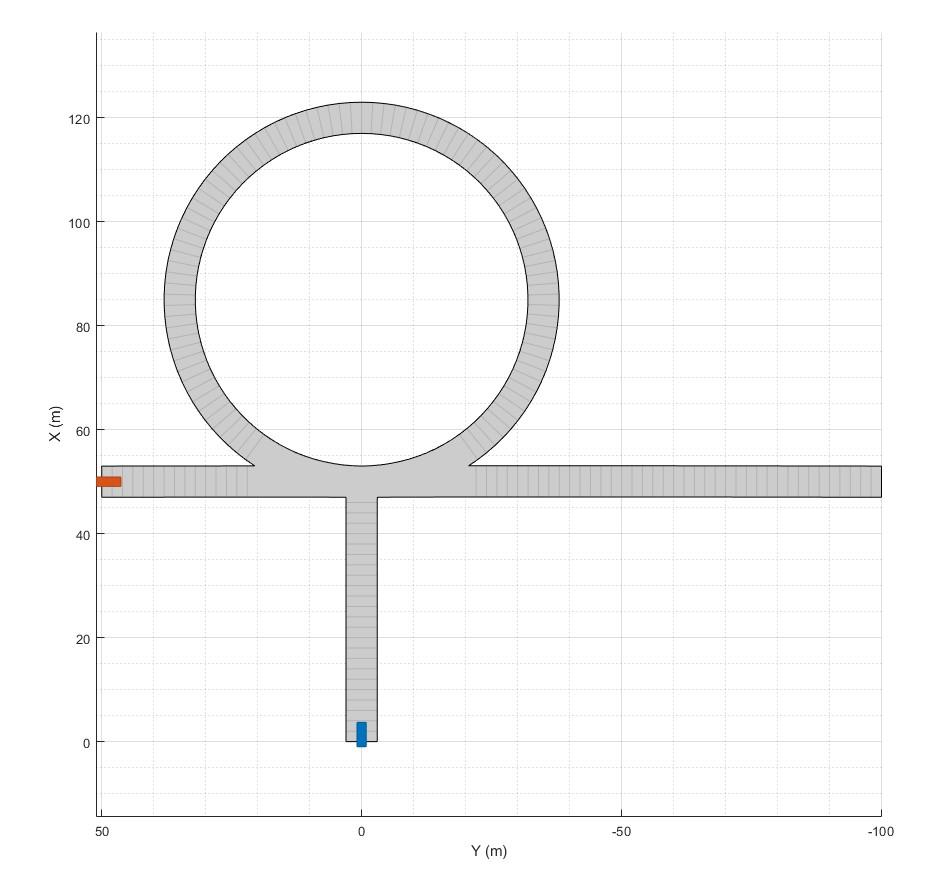

Ego: stands at coordinate origin

Target: straight from left with speed(1)

            ->> 360° turn with speed (1)

            ->> straight to right from speed(1) to speed(2)

% collections=getElements_IMMTester(speed)

**Get the elements of "IMM-Tester (follow)":** 

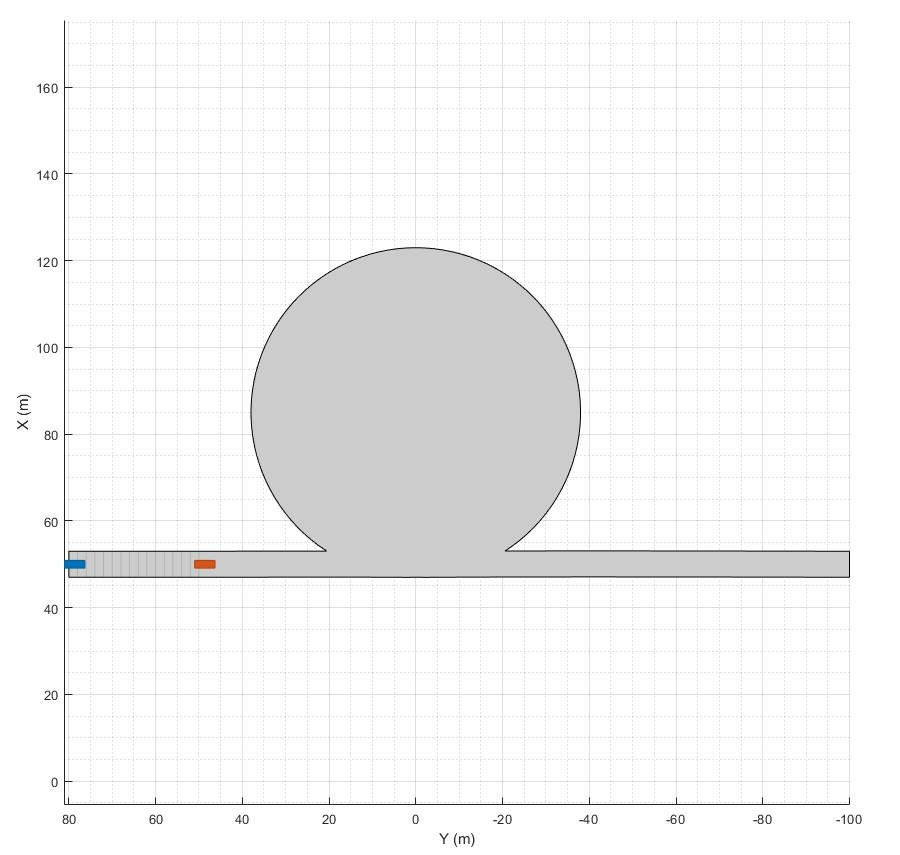

Ego: follows target vehicle with distance(1)

Target: straight from left with speed(1)

            ->> 360° turn with speed (1)

            ->> straight to right from speed(1) to speed(2)

% collections=getElements_IMMFollow(speed,distance)

**Get the elements of "Straight (follow)":** 

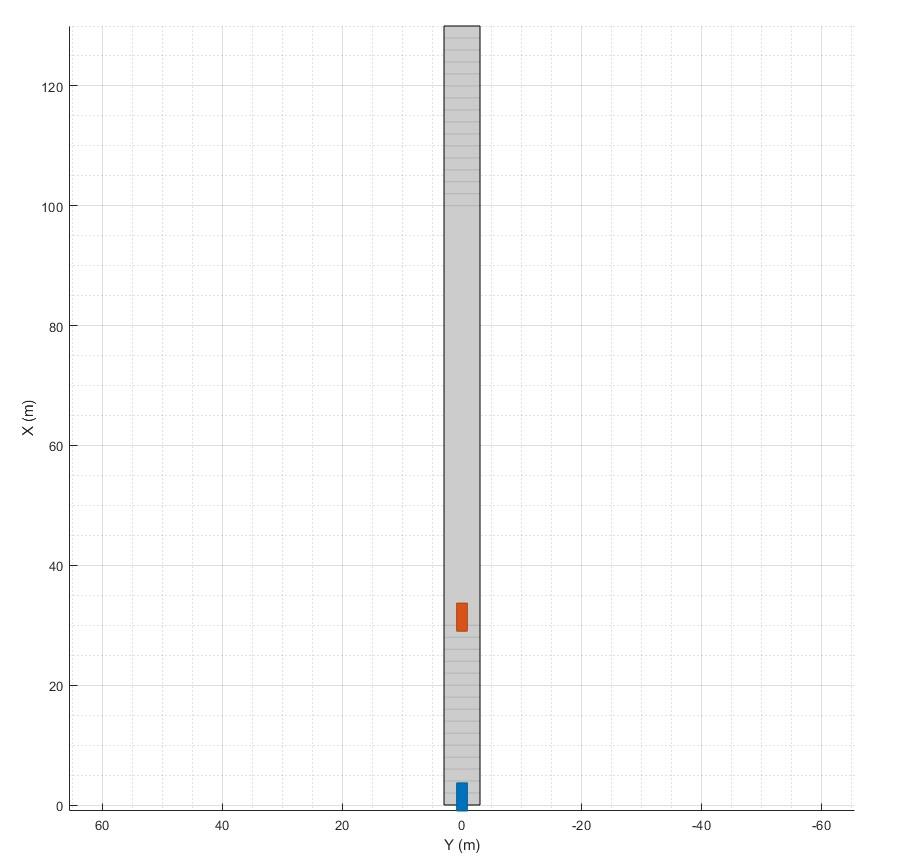

Ego: follows target vehicle with distance(1) and speed(1)

Target: straight with speed(2)

% collections=getElements_StraightFollow(speed,distance)

**Get the elements of "Straight with deceleration":** 

Ego: follows target vehicle with distance(1) and speed(1), then decelerates with deceleration(1)

Target: straight with speed(2), then deceleration(1)

% collections=getElements_DecelerationStraight(speed,distance,deceleration)

**Get the elements of "Curve (follow)":** 

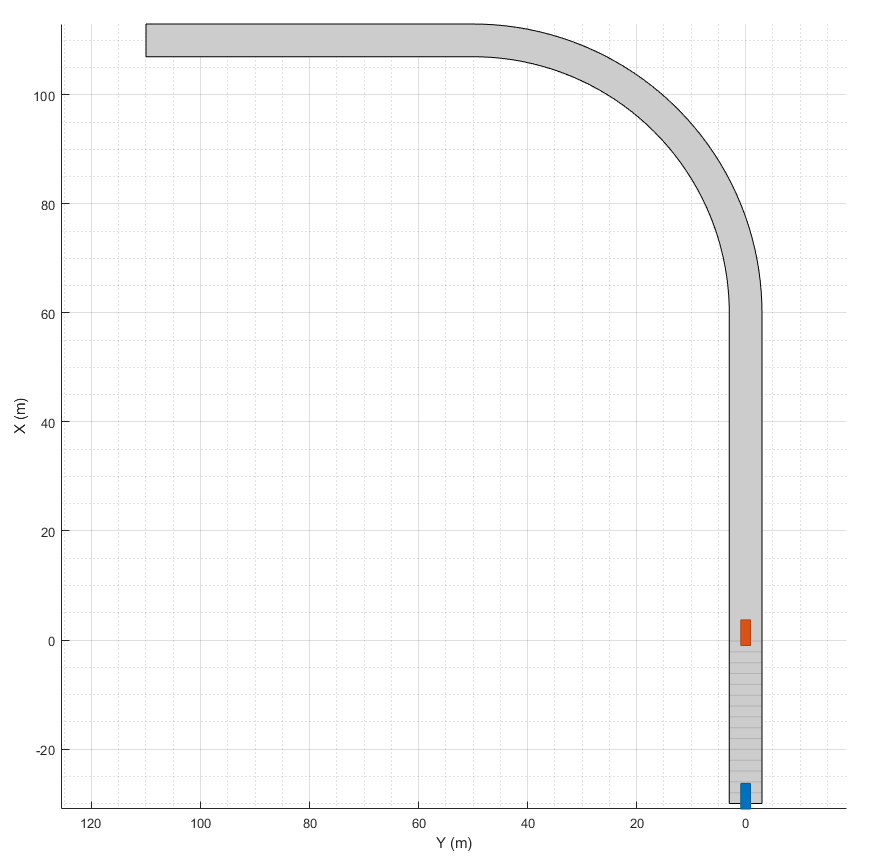

Ego: follows target vehicle with (start)distance(1) and speed(1)

Target: straight with speed(1), then curve with radius(1)

collections=getElements_Curve(speed,distance,radius)

collections = 1×2 struct array with fields:
    classID
    roadPoints
    waypoints
    speeds


**Get the elements of "vehiclesFrontAndBack":** 

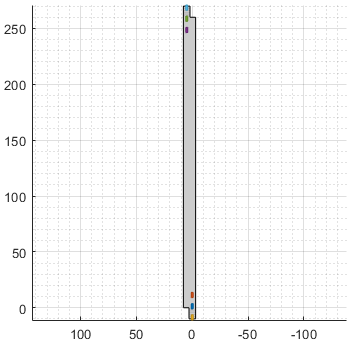

Ego: straight with speed(1)

Targets: straight (3 from top; 1 in back and one in front of ego both to top) with speed(1) and distance between each other,

% collections=getElements_vehicleFrontAndBack(speed,distance)

**Get the elements of "Intersection from left":**

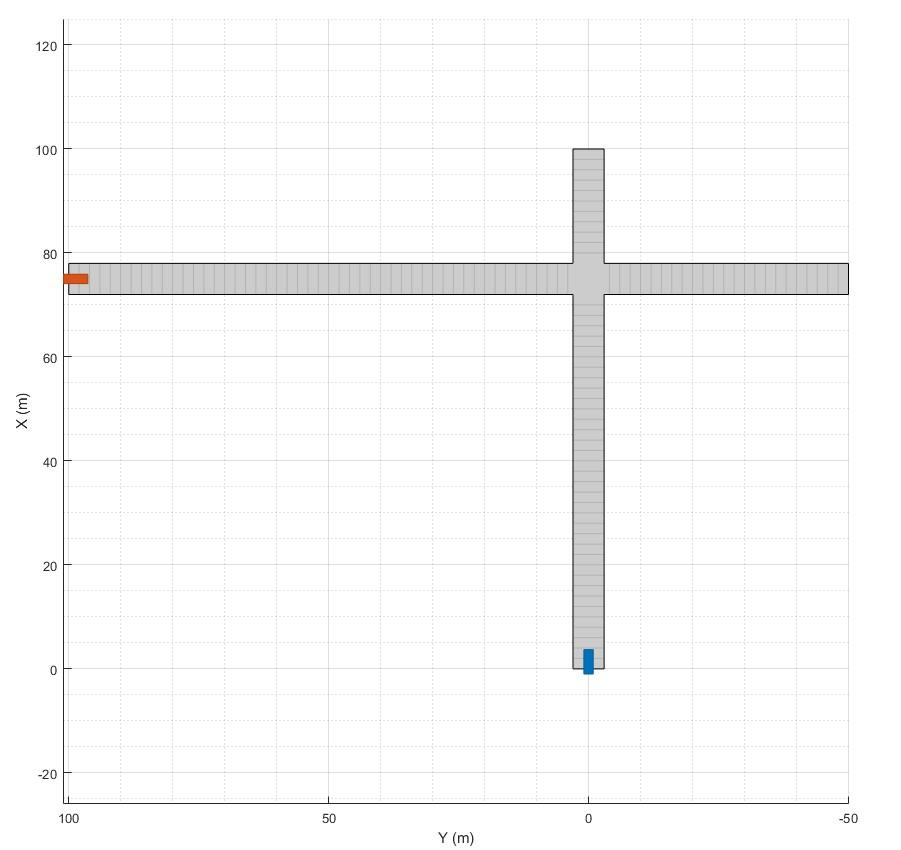

Ego: straight with speed(1)

Target: straight from left with speed(2), then deceleration to 5m left of street with deceleration(1)

% collections=getElements_IntersectionFromLeft(speed,deceleration)

**Get the elements of "Intersection from left & right (observation)":**

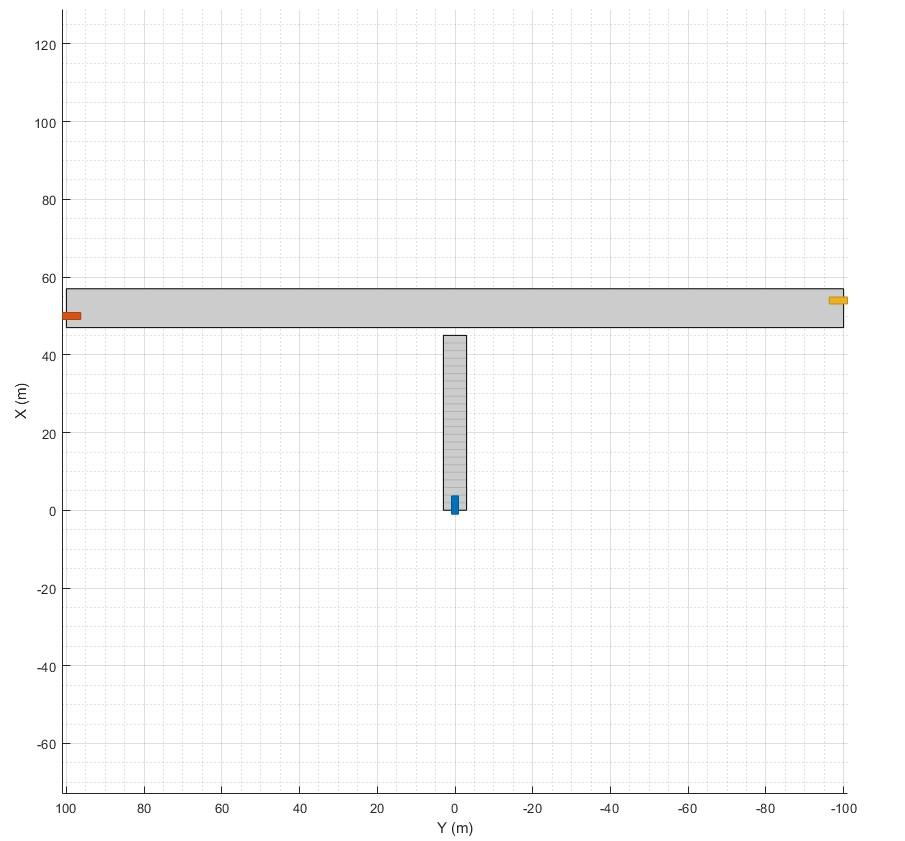

Ego: (stands) at coordinate origin

Target1: straight from left with speed(2)

Target2: straight from right with speed(2) 

% collections=getElements_IntersectionFromLeftAndRight(speed) % ego stands still targets from left and right

**Get the elements of "Complex scenario 1":**

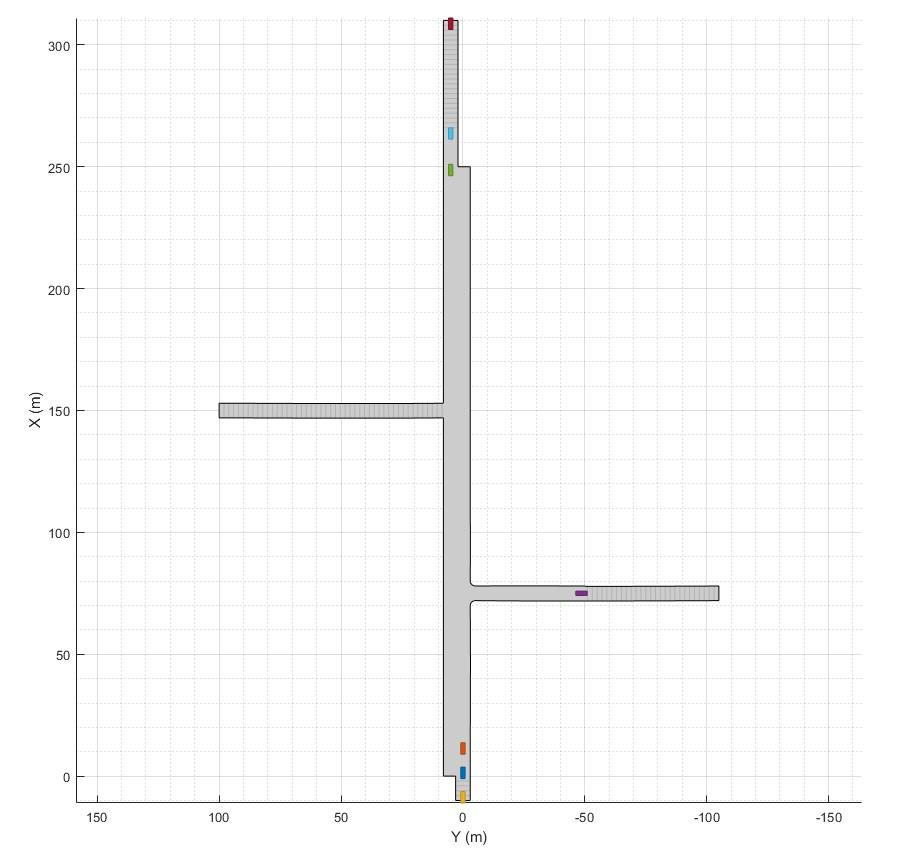

% collections=getElements_Complex1(speed)

## Generating detections and scenario data 

Creation of a drivingScenario object and detection generation with selected sensor-setup.

First of all a drivingScenario is created with the chosen scenario elements (roads, actors and actor trajectories) and the following parameters:

**parameter**                     **default  value   **          **describtion**

sensorSampleTime       0.1s                              describes the sample Time of the sensors

sensorConfigNr             1                                  describes which of the sensor setups is to be used

sensorSampleTime=0.1;
sensorConfigNr=2;

The described elements are collected in the respective arrays for roads/vehicles.

Link to transferElements.

[allRoads,allVehicles,collections]=transferElements(collections);

A driving scenario object is build with the elements of the scenario.

Link to getScenario.

[scenario,egoVehicle]=getScenario(allRoads,allVehicles,sensorSampleTime);

The sensors for the acquisition of detections are defined by choosing a sensor configuration.

1--> blue = camera ; orange = radar

 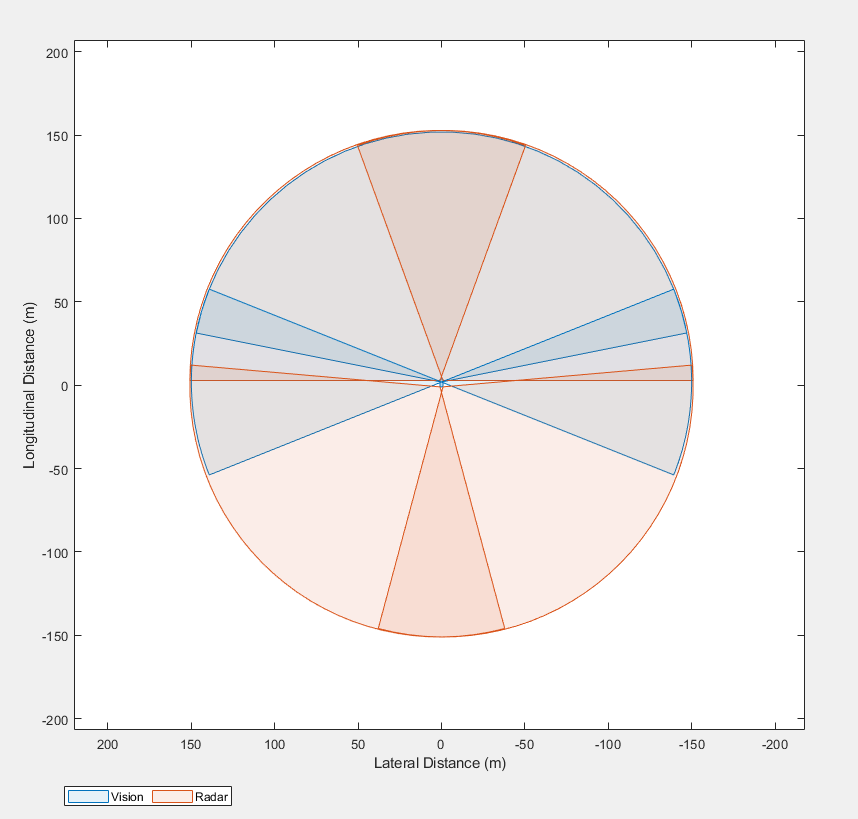

2-->

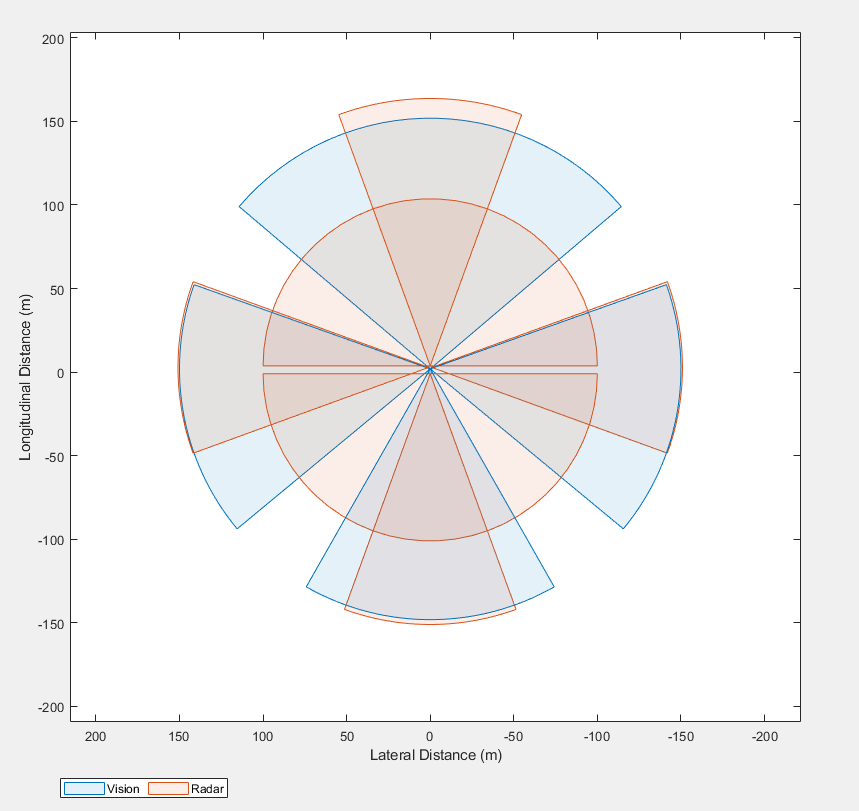

Link to getSensors.

[sensors,numSensors]=getSensors(scenario,sensorSampleTime,sensorConfigNr);

Advancing and extracting detections for every time step of the scenario, till the first vehicle stands still.

Link to getSensorData.

[allData,sensors,scenario]=getSensorData(scenario,egoVehicle,sensors);

Plot the scenario, to see it not only in numbers.

% plot(scenario)
% legend()

## Prefilter detections (cluster algorithm)

Since the designed filters are one-point filters, the detections have to be clustered into a single point per cluster. Although this enables one-point filters, it also means a loss of information and and more noise. Additionally near vehicles could result in a single detection, when clustering not perfectly.

Link to prefilterDetections.

clusterIdeal=0;
idealHasNoise=1;
[allDetections,allClusterSizes]=prefilterDetections(allData,sensors,clusterIdeal,idealHasNoise);

## Evaluate scenario (tracking algorithms)

This part is the main algorithm. Since there are multiple methods possible, the methods which want to be used have to be selected.

The different methods are:

                Assignment method                            Estimation filter

-              GNN                                                 cvKF

-              GNN                                                 IMM

-              JPDA                                                cvKF

-              JPDA                                                IMM

GNN --> Global nearest neighbour

JPDA --> Joint probabilistic data association

cvKF --> constant velocity kalman filter

IMM --> Interacting multiple model filter

numMethods=1:4;

The scenario is then evaluated with every method (defined before with numMethods).

Link to processData.

[result,allbestActors,confirmedTracks]=processData(allData,allDetections,allClusterSizes,scenario,sensors,numMethods,sensorSampleTime);

## Visualize results

For the evaluation of the different methods, the results can be visualized in this section.

At first all still opened windows get closed and the number of actors gets calculated.

close all
numActors=size(allData(1).ActorPoses,1)-1;

The evaluated scenario is shown below.

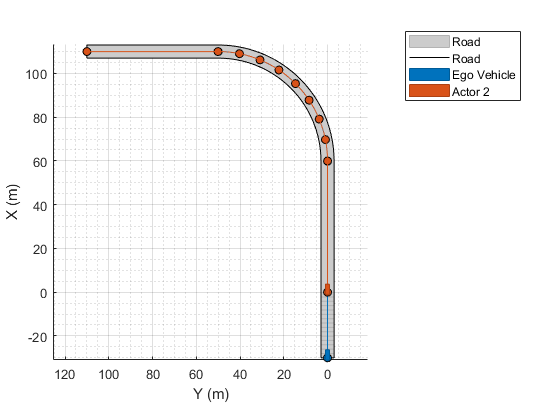

plot(scenario,'Waypoints',"on")
legendNames=["Road" "Road" "Ego Vehicle" (join([repmat("Actor",numActors,1) string(num2str((2:numActors+1)'))]))'];
legend(legendNames)

% title ("Scenario overview")

**Evaluating the clustering process**

At first a overview over the number of detection per actor per time step is visualized for the pre and post clustering state.

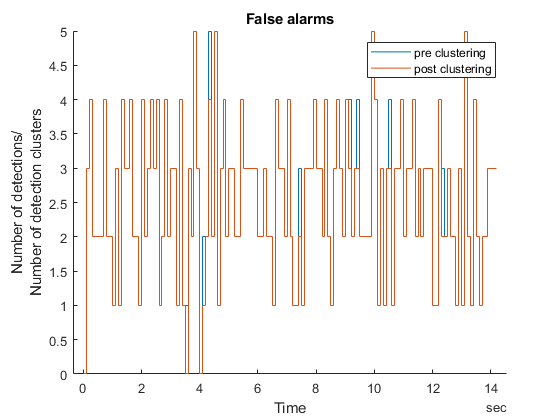

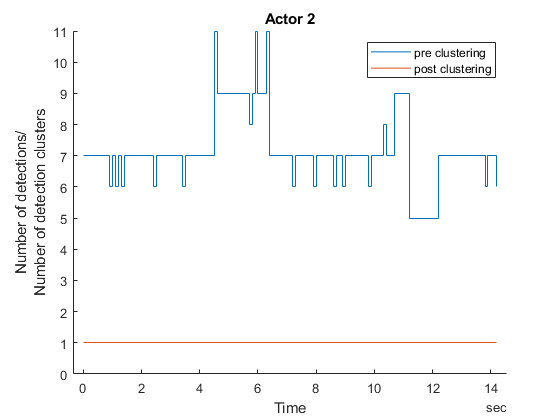

evaluation = 'Actor 2: 143 of 143 time steps detected (100 percent)'

detectionEvaluation(allDetections,numActors,allData)

**Evaluating data association**

Next up is a visualization, which shows, which target the detections that were assigned to the single tracks originate from (origin of the cluster centrum) and their weights (JPDA).

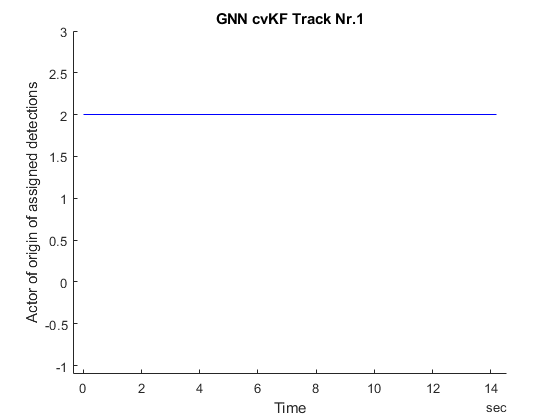

evaluation = 'Actor 2: 143 of 143 time steps (100 percent)'

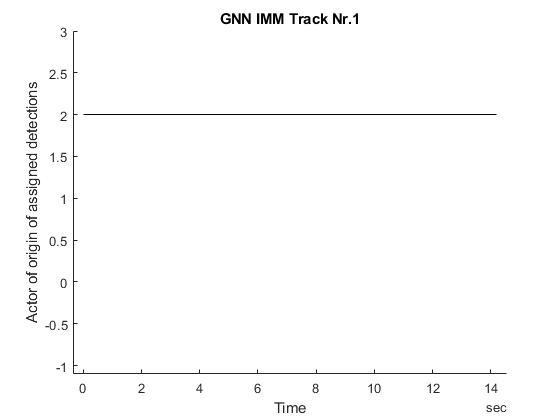

evaluation = 'Actor 2: 143 of 143 time steps (100 percent)'

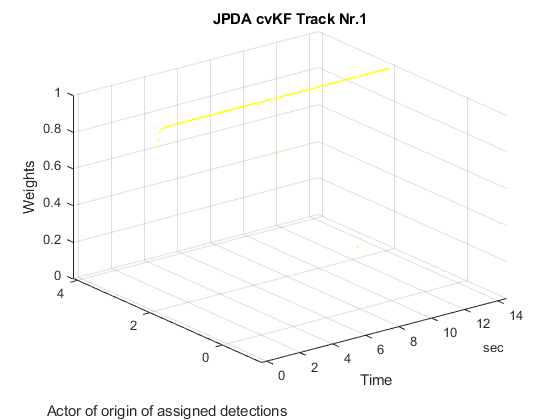

evaluation = 'Actor 2: 143 of 143 detections (100 percent)'

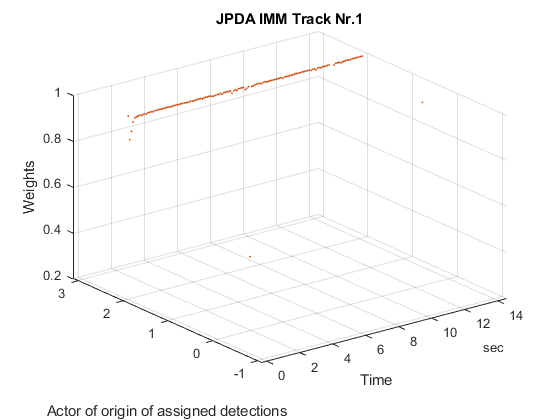

evaluation = 'Actor 2: 141 of 142 detections (99.2958 percent)'

evaluateOcjectID(numMethods,confirmedTracks,allbestActors)

**Evaluating the tracking algorithm**

This function visualizes the position history (x,y) of all confirmed tracks and the real actor position history for every method seperatly.

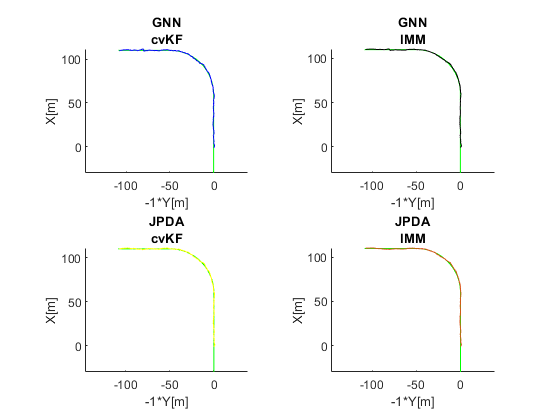

visualizeMap(result,numMethods,numActors)

This function visualizes for every actor and every matched track of every method :

- Range: The difference of the real and estimated euclidean distance from the nearest edge of the actor to the actual track position and its difference to the real distance

- Range direction: The diffference in the real and estimated direction of the nerest actor edge towards the ego vehicle

- Velocity: The actual velocity and the velocity of the matched tracks

- Velocity direction: The actual direction and the direction of the matched tracks (the angles are unwraped: instead of jumping from $\pi$ to $-\pi$ multiples of $2\pi$ are added)

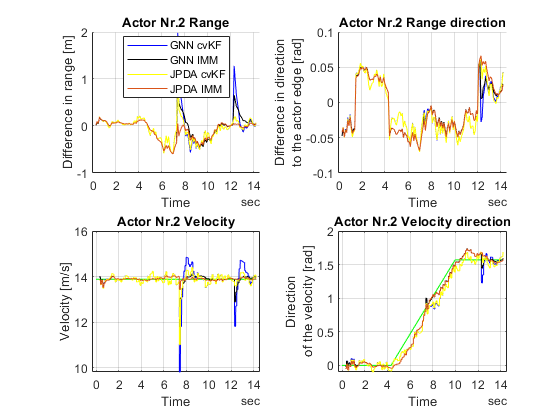

allDifferences=visualizeDifference(result,numMethods,allbestActors,numActors,sensorSampleTime,confirmedTracks);

Plotting the Boxplots of range magnitude, range direction, velocity magnitude, and velocity direction and calculating means,RMSE and standard deviation.

Boxplots show the median of the error values, the respective quartils and the number of outliners. It gives a overview over the position and parameters of the error distribution's values.

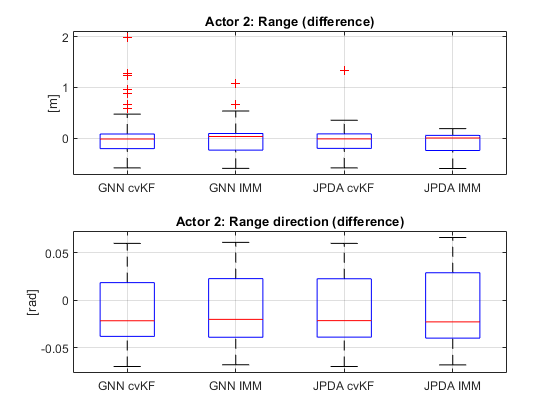

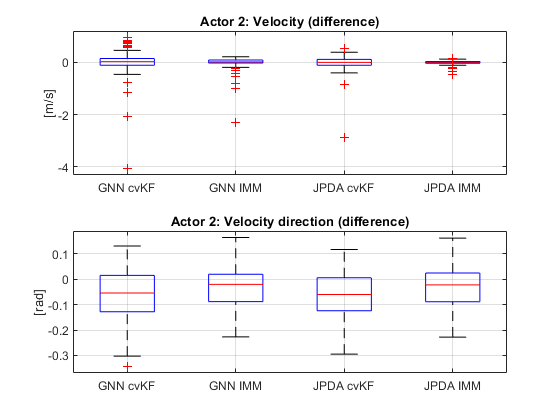

RootMeanSquareError = 4×4 table
                                GNN cvKF    GNN IMM     JPDA cvKF    JPDA IMM
                                ________    ________    _________    ________

    Range [m]                    0.33896     0.26073     0.23904      0.20936
    Range direction [rad]       0.035488    0.035662    0.036393     0.037819
    Velocity[m/s]                0.51418     0.24655     0.30403     0.076433
    Velocity direction [rad]     0.11584    0.091291     0.11043     0.091675


Means = 4×4 table
                                GNN cvKF      GNN IMM      JPDA cvKF     JPDA IMM 
                                _________    __________    _________    __________

    Range [m]                   -0.018638     -0.034752      -0.0552      -0.08316
    Range direction [rad]       -0.011935     -0.010758    -0.010701    -0.0093029
    Velocity[m/s]               0.0034558    -0.0089777     -0.01415     0.0035609
    Velocity direction [rad]    -0.061099     -0.030481    -0.062426      -0.03196


StandardDeviations = 4×4 table
                                GNN cvKF    GNN IMM     JPDA cvKF    JPDA IMM
                                ________    ________    _________    ________

    Range [m]                    0.33967     0.25933     0.23341      0.19283
    Range direction [rad]       0.033541    0.034123     0.03491     0.036788
    Velocity[m/s]                0.51435     0.24647     0.30381     0.076378
    Velocity direction [rad]    0.098451    0.086083    0.091124     0.085954


numActor=5;
[thisRMSE,thisMeans,thisStd]=visualizeBoxPlots(allDifferences,numActor);

This function visualizes the model probabilities of the IMM filter models for:

- GNN+IMM (method 2)

- JPDA+IMM (method 4)

If no specific actorNr is defined, it visualizes the probabilities of the last track.

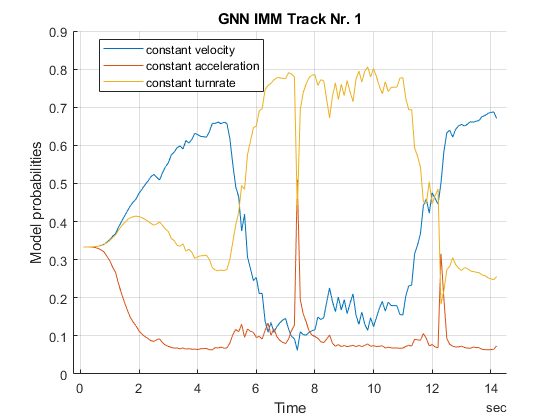

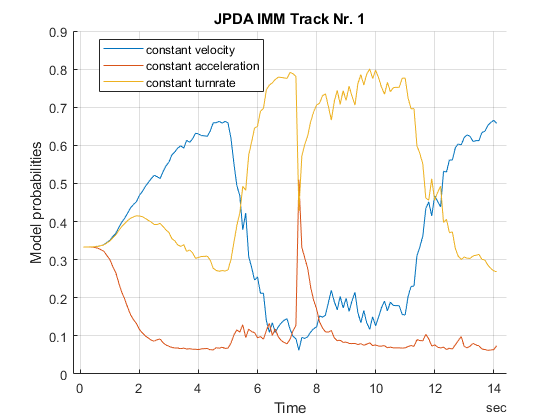

actorNr=2;
visualizeIMMprobs(confirmedTracks,numMethods,actorNr,allbestActors)

**Evaluating multiple simulation runs**

This method takes the last runs, since the last reset of the history values (allErrors,allMeans,allStd) into account, to build a mean evaluation over multiple runs.

if(exist('allErrors','var'))
    allErrors(:,:,end+1)=thisRMSE;
    allMeans(:,:,end+1)=thisMeans;
    allStd(:,:,end+1)=thisStd;
else
    allErrors=thisRMSE;
    allMeans=thisMeans;
    allStd=thisStd;
end
allLabels=["GNN cvKF" "GNN IMM" "JPDA cvKF" "JPDA IMM"];
rNames=["Range [m]" "Range direction [rad]" "Velocity[m/s]" "Velocity direction [rad]"];
plotError=mean(allErrors,3);
NumberofRuns=size(allErrors,3)

NumberofRuns = 1

MeanOfRootMeanSquareError=table(plotError(:,1),plotError(:,2),plotError(:,3),plotError(:,4),'VariableNames',allLabels,'RowNames',rNames)

MeanOfRootMeanSquareError = 4×4 table
                                GNN cvKF    GNN IMM     JPDA cvKF    JPDA IMM
                                ________    ________    _________    ________

    Range [m]                    0.33896     0.26073     0.23904      0.20936
    Range direction [rad]       0.035488    0.035662    0.036393     0.037819
    Velocity[m/s]                0.51418     0.24655     0.30403     0.076433
    Velocity direction [rad]     0.11584    0.091291     0.11043     0.091675


plotMean=mean(allMeans,3);
meanOfMeans=table(plotMean(:,1),plotMean(:,2),plotMean(:,3),plotMean(:,4),'VariableNames',allLabels,'RowNames',rNames)

meanOfMeans = 4×4 table
                                GNN cvKF      GNN IMM      JPDA cvKF     JPDA IMM 
                                _________    __________    _________    __________

    Range [m]                   -0.018638     -0.034752      -0.0552      -0.08316
    Range direction [rad]       -0.011935     -0.010758    -0.010701    -0.0093029
    Velocity[m/s]               0.0034558    -0.0089777     -0.01415     0.0035609
    Velocity direction [rad]    -0.061099     -0.030481    -0.062426      -0.03196


plotStd=mean(allStd,3);
meanOfStandardDeviation=table(plotStd(:,1),plotStd(:,2),plotStd(:,3),plotStd(:,4),'VariableNames',allLabels,'RowNames',rNames)

meanOfStandardDeviation = 4×4 table
                                GNN cvKF    GNN IMM     JPDA cvKF    JPDA IMM
                                ________    ________    _________    ________

    Range [m]                    0.33967     0.25933     0.23341      0.19283
    Range direction [rad]       0.033541    0.034123     0.03491     0.036788
    Velocity[m/s]                0.51435     0.24647     0.30381     0.076378
    Velocity direction [rad]    0.098451    0.086083    0.091124     0.085954


## 3D Animation

The best way to visualize the time depentend values, is a 3D Animation.

This Animation shows:

The **Ego** vehicle as a **red** vehicle.

The **Actor** vehicle as a **green** vehicles.

The **GNN cvKF** tracks as **blue **vehicles.

The **GNN IMM** tracks as **black **vehicles.

The **JPDA cvKF** tracks as **yellow **vehicles.

The **JPDA IMM** tracks as **orange **vehicles.

Which methods should get animated?

numMethods2Show=1:4;

On which actor should the camera be positioned on.

cameraOnActorNr=2;

Animate the scenario and the emasurement.

% visualizeScenario(numMethods,result,numActors,numMethods2Show,cameraOnActorNr)

Back to top.

## ----------------------------------------------------------------------------------------------------------------------------------------------------------------------------

# Helper functions

## Generating sensor data

### e.g. getElements_IMMTester ( = build a scenario)

This function creates the data which is used in the next step to build all vehicles and roads used in the scenario.

The scenario builded in this example is shown in the following picture.

egoVehicle: stand still in the scenario's origin

targetVehicle:

- straight segment with velocity (1)

- circle segment with velocity (1) and radius 35 m

- acceleration segment from velocity (1) to velocity (2) in 100m

The used variables vary for the different scenarios!

Variables In (**in general**):

speed --> describtion of the velocity of the different vehicles in the scenario

distance --> describtion of the distance between certain vehicles in the scenario

deceleration--> describtion of the deceleration of different vehicles in the scenario

radius--> describtion of the curve radius in the scenario

Variables Out (**in general**):

collections --> describtion of roads and vehicles in the scenario

function collections=getElements_IMMTester(speed)

The eco vehicle is defined first. The following values have to be choosen:

- classID: the vehicle ID declares what kind of vehicle the created vehicle represents

- roadPoints: the road points define the street on which the vehicle is driving

- waypoints: declare the waypoints, which are used to create the trajectory of the vehicle

- speeds: defines the velocity of the vehicle at the respective waypoint

If the vehicle stands still, so just has one waypoint, the yaw property has to be set instead of speeds.

- yaw: defines the direction the vehicle is heading to

Optional the property waitTime can be assigned. 

- waitTime: the vehicle holds its position for the duration (waitTime value in seconds) at the respective waypoints

In this case the ego vehicle stands still and is directed in the X direction.

collections(1,1).classID=1;
collections(1,1).roadPoints=[0,0,0;50,0,0];
collections(1,1).waypoints=[0,0,0];
collections(1,1).yaw=0;

The target vehicle has the three segments described above.

1.) straight with velocity (1)

segment1=[50,50,0;50,1,0];
speed1=speed(1)*ones(2,1);

2.) circle with radius 35m and velocity (1)

angles=-pi:pi/8:pi;
angles=angles';
segment2=35*[cos(angles)+ones(numel(angles),1) sin(angles) zeros(numel(angles),1)];
segment2=segment2+repmat([50 0 0],numel(angles),1);
speed2=speed(1)*ones(numel(angles),1);

3.) acceleration from velocity (1) to velocity (2) in 100m

segment3=[50,-1,0;50,-100,0];
speed3=[speed(1);speed(2)];

Adding all segments together to describe the whole movement of the target vehicle and the road it is driving on.

collections(1,2).classID=1;
collections(1,2).roadPoints=[segment1;segment2;segment3];
collections(1,2).waypoints=[segment1;segment2;segment3];
collections(1,2).speeds=[speed1;speed2;speed3];
end

Back to top.

Back to usage.

----------------------------------------------------------------------------------------------------------------------------------------------------------------------------

### transferElements ( = collecting scenario elements)

this function devides the collections created by the different scenario building functions before (e.g **getElements_IMMTester**), into a vehicle (allVehicles) and road collection (allRoads).

Variables In:

collections --> describtion of the elements in the scenario (output of e.g **getElements_IMMTester**)

Variables Out:

allRoads --> all roads in the current scenario

allVehicles --> all vehicles in the current scenario

function [allRoads,allVehicles,collections]=transferElements(collections)

Every element of the collection gets transfered in the allVehicle and allRoads collection.

for i=1:numel(collections)

    If there was no waitTime defined in this element in the collection, waitTime is set to zero for every waypoint.

    if ~isfield(collections(1,i),'waitTime')
        collections(1,i).waitTime=zeros(size(collections(1,i).speeds));
    elseif isempty(collections(1,i).waitTime)
        collections(1,i).waitTime=zeros(size(collections(1,i).speeds));
    end

    The roadPoints are accumulate in the allRoads collection.

    allRoads{i,1}=collections(1,i).roadPoints;

    ClassID, waypoints, velocity, yaw and waitTime are assembled into a new vehicle in the allVehicles collection.

    allVehicles(i,1).waypoints=collections(1,i).waypoints;
    allVehicles(i,1).classID=collections(1,i).classID;

    Standing vehicles need a yaw value instead of a speeds value.

    if size(allVehicles(i,1).waypoints,1)==1
        allVehicles(i,1).yaw=collections(1,i).yaw;
    else
        allVehicles(i,1).speeds=collections(1,i).speeds;
        allVehicles(i,1).waitTime=collections(1,i).waitTime;
    end
end
end

Back to top.

Back to usage.

----------------------------------------------------------------------------------------------------------------------------------------------------------------------------

### getScenario ( = initializing a scenario object)

The roads and vehicles of the scenario are fused into a **drivingScenario** Matlab object.

Variables In:

allRoads --> all roads in the current scenario (output of **transferElements**)

allVehicles --> all vehicles in the current scenario (output of **transferElements**)

sensorSampleTime --> sample time of all sensors

Variables Out:

scenario --> the driving scenario object that represents the scenario

egoVehicle --> the actor defined as ego vehicle

function [scenario,egoVehicle] = getScenario(allRoads,allVehicles,sensorSampleTime)

To take the sensor sample Time into account, the SampleTime property of the initialized drivingScenario is set to that of the sensors.

The **drivingScenario** - function of Matlab is used here. ([https://de.mathworks.com/help/driving/ref/drivingscenario.html](https://de.mathworks.com/help/driving/ref/drivingscenario.html))

scenario = drivingScenario('SampleTime',sensorSampleTime);

All roads (allRoads) are added to the scenario. Therefore the **road** - function of Matlab is used. ([https://de.mathworks.com/help/driving/ref/drivingscenario.road.html](https://de.mathworks.com/help/driving/ref/drivingscenario.road.html))

for i=1:numel(allRoads)
    road(scenario,allRoads{i,1})
end

All vehicles (allVehicles) are added to the scenario

for i=1:numel(allVehicles)
    thisVeh=allVehicles(i,1);

To assign the vehicles to the scenario, the **vehicle** - function of Matlab needs to be used. ([https://de.mathworks.com/help/driving/ref/drivingscenario.vehicle.html](https://de.mathworks.com/help/driving/ref/drivingscenario.vehicle.html))

**The ego vehicle has to be the ****FIRST**** vehicle assigned!**

    if i==1

If the ego vehicle is just standing still, only its yaw has to be assigned instead of its velocity (speeds) and a wait time (waitTime) for every waypoint (waypoints).

        if size(thisVeh.waypoints,1)==1
            egoVehicle=vehicle(scenario,'ClassID',thisVeh.classID,...
                'Position', thisVeh.waypoints,'Yaw',thisVeh.yaw);

Else both the velocitys (speeds) and the wait times (waitTime) have to be assigned, because they define the vehicles yaw by there own.

To add the trajectory to the scenario, the **trajectory** - function of Matlab is used. ([https://de.mathworks.com/help/driving/ref/drivingscenario.trajectory.html](https://de.mathworks.com/help/driving/ref/drivingscenario.trajectory.html))

        else
            egoVehicle=vehicle(scenario,'ClassID',thisVeh.classID,...
                'Position', thisVeh.waypoints(1,:));
            trajectory(egoVehicle,thisVeh.waypoints,thisVeh.speeds,thisVeh.waitTime);
        end

All the target vehicles in the respective collection are added after the ego vehicle. They are treated the same way like the ego vehicle in regard to vehicles that stand still and vehicles that need a trajectory assigned.

    else
        if size(thisVeh.waypoints,1)==1
            thisVehicle=vehicle(scenario,'ClassID',thisVeh.classID,...
                'Position', thisVeh.waypoints(1,:),'Yaw',thisVeh.yaw);
        else
            thisVehicle=vehicle(scenario,'ClassID',thisVeh.classID,...
                'Position', thisVeh.waypoints(1,:));
            trajectory(thisVehicle,thisVeh.waypoints,thisVeh.speeds,thisVeh.waitTime);
        end
    end
end
end

Back to top.

Back to usage.

----------------------------------------------------------------------------------------------------------------------------------------------------------------------------

### getSensors ( = setup sensor configuration)

For generating sensor detections, sensors are needed. This function loads the demanded sensor configuration specified by the configNr and sets its sensor's sample time to sensorSampleTime.

Variables In:

scenario --> the driving scenario object, which should get evaluated (output of **getScenario**)

sensorSampleTime --> sample time of all sensors

configNr --> identifier of the sensor configuration

Variables Out:

allSensors --> all sensors in the current configuration

numSensors --> number of sensors in the configuration

function [allSensors,numSensors]=getSensors(scenario,sensorSampleTime,configNr)

The different actor profiles (physical and radar characteristics) are extracted from the scenario object by using the **actorProfiles** - function of Matlab. ([https://de.mathworks.com/help/driving/ref/drivingscenario.actorprofiles.html](https://de.mathworks.com/help/driving/ref/drivingscenario.actorprofiles.html))

profiles = actorProfiles(scenario);

Multiple sensor configurations can be implemented. The easiest way to create them is to use the **Driving Scenario Designer** by Matlab. 

switch configNr

Configuration 1 contains (blue = camera; orange = radar):

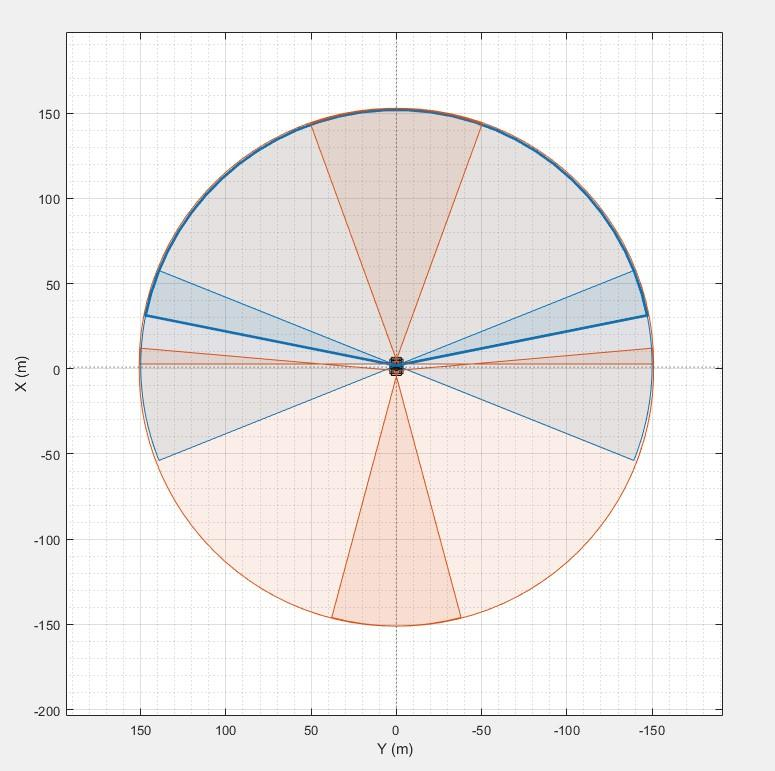

    case 1

- camera (front)

        allSensors{1} = visionDetectionGenerator('SensorIndex', 1, ...
            'UpdateInterval', sensorSampleTime, ...
            'SensorLocation', [1.9 0], ...
            'DetectorOutput', 'Objects only', ...
            'Intrinsics', cameraIntrinsics([800 800],[5000 240],[480 8000]), ...
            'ActorProfiles', profiles);

- radar (front left)

        allSensors{2} = radarDetectionGenerator('SensorIndex', 2, ...
            'UpdateInterval', sensorSampleTime, ...
            'SensorLocation', [2.8 0.9], ...
            'Yaw', 35, ...
            'ReferenceRange', 150, ...
            'FieldOfView', [110 5], ...
            'ActorProfiles', profiles);

- radar (front right)

        allSensors{3} = radarDetectionGenerator('SensorIndex', 3, ...
            'UpdateInterval', sensorSampleTime, ...
            'SensorLocation', [2.8 -0.9], ...
            'Yaw', -35, ...
            'FieldOfView', [110 5], ...
            'ActorProfiles', profiles);

- camera (left)

        allSensors{4} = visionDetectionGenerator('SensorIndex', 4, ...
            'UpdateInterval', sensorSampleTime, ...
            'SensorLocation', [1.9 0], ...
            'Yaw', 90, ...
            'DetectorOutput', 'Objects only', ...
            'Intrinsics', cameraIntrinsics([800 800],[320 240],[480 640]), ...
            'ActorProfiles', profiles);

- camera (right)

        allSensors{5} = visionDetectionGenerator('SensorIndex', 5, ...
            'UpdateInterval', sensorSampleTime, ...
            'SensorLocation', [1.9 0], ...
            'Yaw', -90, ...
            'DetectorOutput', 'Objects only', ...
            'ActorProfiles', profiles);

- radar (rear/left)

        allSensors{6} = radarDetectionGenerator('SensorIndex', 6, ...
            'UpdateInterval', sensorSampleTime, ...
            'SensorLocation', [-1 0.9], ...
            'Yaw', 140, ...
            'FieldOfView', [110 5], ...
            'ActorProfiles', profiles);

- radar (rear/right)

        allSensors{7} = radarDetectionGenerator('SensorIndex', 7, ...
            'UpdateInterval', sensorSampleTime, ...
            'SensorLocation', [-1 -0.9], ...
            'Yaw', -140, ...
            'FieldOfView', [110 5], ...
            'ActorProfiles', profiles);
        numSensors=7;
    case 2
        allSensors{1} = visionDetectionGenerator('SensorIndex', 1, ...
            'SensorLocation', [1.9 0], ...
            'DetectorOutput', 'Objects only', ...
            'Intrinsics', cameraIntrinsics([870 640],[1024 640],[1280 2048]), ...
            'ActorProfiles', profiles);
        allSensors{2} = radarDetectionGenerator('SensorIndex', 2, ...
            'SensorLocation', [3.7 0], ...
            'MaxRange', 100, ...
            'ReferenceRange', 150, ...
            'FieldOfView', [180 5], ...
            'ActorProfiles', profiles);
        allSensors{3} = radarDetectionGenerator('SensorIndex', 3, ...
            'SensorLocation', [2.8 -0.9], ...
            'Yaw', -90, ...
            'HasOcclusion', false, ...
            'FieldOfView', [40 5], ...
            'ActorProfiles', profiles);
        allSensors{4} = visionDetectionGenerator('SensorIndex', 4, ...
            'SensorLocation', [1.9 0], ...
            'Yaw', 100, ...
            'DetectorOutput', 'Objects only', ...
            'Intrinsics', cameraIntrinsics([1800 640],[1024 640],[1280 2048]), ...
            'ActorProfiles', profiles);
        allSensors{5} = visionDetectionGenerator('SensorIndex', 5, ...
            'SensorLocation', [1.9 0], ...
            'Yaw', -100, ...
            'DetectorOutput', 'Objects only', ...
            'Intrinsics', cameraIntrinsics([1800 640],[1024 640],[1280 2048]), ...
            'ActorProfiles', profiles);
        allSensors{6} = radarDetectionGenerator('SensorIndex', 6, ...
            'SensorLocation', [-1 0], ...
            'Yaw', -180, ...
            'FieldOfView', [40 5], ...
            'ActorProfiles', profiles);
        allSensors{7} = radarDetectionGenerator('SensorIndex', 7, ...
            'SensorLocation', [3.7 0], ...
            'MaxRange', 160, ...
            'HasOcclusion', false, ...
            'FieldOfView', [40 5], ...
            'ActorProfiles', profiles);
        allSensors{8} = radarDetectionGenerator('SensorIndex', 8, ...
            'SensorLocation', [2.8 0.9], ...
            'Yaw', 90, ...
            'FieldOfView', [40 5], ...
            'ActorProfiles', profiles);
        allSensors{9} = radarDetectionGenerator('SensorIndex', 9, ...
            'SensorLocation', [-1 0], ...
            'Yaw', -180, ...
            'MaxRange', 100, ...
            'ReferenceRange', 150, ...
            'FieldOfView', [180 5], ...
            'ActorProfiles', profiles);
        allSensors{10} = visionDetectionGenerator('SensorIndex', 10, ...
            'SensorLocation', [1.9 0], ...
            'Yaw', 180, ...
            'DetectorOutput', 'Objects only', ...
            'Intrinsics', cameraIntrinsics([1800 800],[1024 640],[1280 2048]), ...
            'ActorProfiles', profiles);
        numSensors = 10;
end
end

Back to top.

Back to usage.

----------------------------------------------------------------------------------------------------------------------------------------------------------------------------

### getSensorData ( = generating detections for the previous builded scenario)

**The function is extracted from an automated generated function from the driving scneario designer from Matlab.**

Variables In:

scenario --> the driving scenario object, which should get evaluated (output of **getScenario**)

egoVehicle --> the actor defined as ego vehicle (output of **getScenario**)

sensors --> all sensors in the current sensor configuration (output of **getSensor**)

Variables Out:

allData --> contains the detections and actor poses for every time step 

sensors --> all sensors in the current sensor configuration (output of **getSensor**)

scenario --> the driving scenario object, which should get evaluated (output of **getScenario**)

function [allData,sensors,scenario]=getSensorData(scenario,egoVehicle,sensors)
numSensors=numel(sensors);
allData = struct('Time', {}, 'ActorPoses', {}, 'ObjectDetections', {}, 'LaneDetections', {});
running = true;
while running
    
    % Generate the target poses of all actors relative to the ego vehicle
    poses = targetPoses(egoVehicle);
    time  = scenario.SimulationTime;
    
    objectDetections = {};
    laneDetections   = [];
    isValidTime      = false(1, numSensors);
    
    % Generate detections for each sensor
    for sensorIndex = 1:numSensors
        sensor = sensors{sensorIndex};
        [objectDets, numObjects, isValidTime(sensorIndex)] = sensor(poses, time);
        objectDetections = [objectDetections; objectDets(1:numObjects)]; %#ok<AGROW>
    end
    
    % Aggregate all detections into a structure for later use
    if any(isValidTime)
        allData(end + 1) = struct( ...
            'Time',       scenario.SimulationTime, ...
            'ActorPoses', actorPoses(scenario), ...
            'ObjectDetections', {objectDetections}, ...
            'LaneDetections',   {laneDetections}); %#ok<AGROW>
    end
    
    % Advance the scenario one time step and exit the loop if the scenario is complete
    running = advance(scenario);
end

% Restart the driving scenario to return the actors to their initial positions.
restart(scenario);

% Release all the sensor objects so they can be used again.
for sensorIndex = 1:numSensors
    release(sensors{sensorIndex});
end
end

Back to top.

Back to usage.

----------------------------------------------------------------------------------------------------------------------------------------------------------------------------

## Detection clustering

### prefilterDetections ( =detection clustering & transformation)

Because the filters work in the global coordinate system and need a single detection per object, the detections have to be 

- transformed to global coordinates

- clustered into detection clusters

Variables In:

allData --> contains the detections and actor poses for every time step (output of **getSensorData**)

sensors --> contains all the sensors used in the current sensor setup (output of **getSensors**)

Variables Out:

allDetections --> contains all the detection clusters

allClusterSizes --> contains the number of detections clustered together in the respective cluster

function [allDetections,allClusterSizes]=prefilterDetections(allData,sensors,clusterIdeal,idealHasfalseAlarms)

For the case, that the measured velocitys in the detections are needed at some point later in the MOBATSim project, they need to be transformed correctly.

Therefore it is necessary to divide between radar detections (doppler velocity) and camera detections (directed velocity).

The sensor's type is saved in sensorTypes.

sensorTypes=string([]);
for numSensor=1:size(sensors,2)
    if isa(sensors{numSensor},'radarDetectionGenerator')
        sensorTypes(end+1)="Radar";
    elseif isa(sensors{numSensor},'visionDetectionGenerator')
        sensorTypes(end+1)="Camera";
    end
end

All detections (for every time step) need to be transformed and clustered.

for thisTimeFrame=1:numel(allData)

The detections are loaded from the ObjectDetections property of the data generated from the **getSensorData** - function.

**format of "allData"-struct **

**format of "ObjectDetections"**

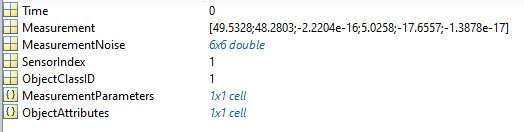

    data=allData(thisTimeFrame);
    detectionsRaw=data.ObjectDetections;
    detectionsRadar={};
    detectionsCamera={};

To transform the detections correctly and change the cluster threshold based on the distance to the ego vehicle, the position of the ego vehicle is needed.

**Format of "ActorPoses"**

    egoPosition=allData(thisTimeFrame).ActorPoses(1).Position';

The detections are sorted towards their sensor type (radar and camera detections).    

    for numDetection=1:length(detectionsRaw)
        switch sensorTypes(detectionsRaw{numDetection,1}.SensorIndex)
            case "Radar"
                detectionsRadar=[detectionsRadar; detectionsRaw(numDetection,1)];
            case "Camera"
                detectionsCamera=[detectionsCamera; detectionsRaw(numDetection,1)];
        end
    end

The detections are now transformed to the global coordinates, using the  **transform2global** - function.

Link to transform2global.

    egoState=allData(thisTimeFrame).ActorPoses(1);
    detectionsRadar=transform2global(detectionsRadar,sensorTypes,egoState);
    detectionsCamera=transform2global(detectionsCamera,sensorTypes,egoState);

They now are combined in the theseDetection array.

    theseDetections=[detectionsRadar;detectionsCamera];

Since the implemented cluster algorithm is not that accurate, there is an alternative option to filter the detections ideal.

    if (clusterIdeal)
        detectionClusters=cell(0,0);
        clusterSizes=[];

Therefore for every actor only the nearest detection is NOT deleted.

        allOrigins=cellfun(@(x) x.ObjectAttributes{1,1}.TargetIndex,theseDetections);
        uniqueIds=unique(allOrigins);
        for id=uniqueIds'
            if(id~=-1)
                thisDetections=theseDetections{allOrigins==id};
                thesePositions=[thisDetections(:,1).Measurement];
                thesePositions=thesePositions(1:2,:);
                diffPositions=thesePositions-egoState.Position(1,1:2)';
                distance2Ego=vecnorm(diffPositions,2,1);
                [~,nearestIdx]=min(distance2Ego);
                bestDet=thisDetections(nearestIdx);
                bestDet.Measurement=bestDet.Measurement([1 2 4 5],1);
                measNoise(1:2,1:2)=2*eye(2);
                measNoise(3:4,3:4)=3600*eye(2);
                bestDet.MeasurementNoise=measNoise;
                detectionClusters(end+1,1)={bestDet};                
                clusterSizes(end+1)=sum(allOrigins==id);
            end
        end

The user can switch between keeping or deleting all false alarms.

        if idealHasfalseAlarms
            for numDet=1:numel(allOrigins)
                if (allOrigins(numDet)==-1)
                    bestDet=theseDetections{numDet};
                    bestDet.Measurement=bestDet.Measurement([1 2 4 5],1);
                    measNoise(1:2,1:2)=2*eye(2);
                    measNoise(3:4,3:4)=3600*eye(2);
                    bestDet.MeasurementNoise=measNoise;
                    detectionClusters(end+1,1)={bestDet};
                    clusterSizes(end+1)=sum(allOrigins==id);
                end
            end
        end
        
    else

Alternatively the normal cluster algorithm is used

To cluster the detections, the euclidean distances between all of them are calculated.

    numDetections=numel(theseDetections);
    allDistances=zeros(numDetections);
    clusterSizes=[];
    for i=1:numDetections
        for j=1:numDetections
            allDistances(i,j)=norm(theseDetections{i}.Measurement(1:2)-theseDetections{j}.Measurement(1:2));
        end
    end

Every detection has to be part of a cluster.

    notClustered=1:numDetections;
    i=0;
    detectionClusters=cell(numDetections,1);

Repeat, while not all detections clustered.

    while ~isempty(notClustered)

Get all indices of camera detections .

        allClassIds=cellfun(@(x) x.ObjectClassID,theseDetections(notClustered));
        idDetectionsIdx=find(allClassIds~=0);

If there is a detection available where the actor is identified, the next cluster is build around one.

        if ~isempty(idDetectionsIdx)
            thisReference=notClustered(idDetectionsIdx(1));
            
        else
            thisReference=notClustered(1);
        end
        thisObjectId=theseDetections{thisReference,1}.ObjectClassID;

Based on the distance to the ego vehicle and the connected increasing noise, the clustering threshold distance is increased by a factor (distFactor)

        dist2ego=norm(theseDetections{thisReference,1}.Measurement(1:2)-egoPosition(1:2));
        if dist2ego<=50
            distFactor=1+0.2/50*dist2ego;
        elseif dist2ego<=100
            distFactor=1.2+0.3*(dist2ego-50)/50;
        else
            distFactor=1.5;
        end

If the reference sensor identifies an actor type, the cluster threshold is calculated based on the identified actor's dimension. 

        if (thisObjectId~=0)
            sensorId=theseDetections{thisReference,1}.SensorIndex;
            clusterThreshold=sensors{sensorId}.ActorProfiles(thisObjectId,1).Width+...
                sensors{sensorId}.ActorProfiles(thisObjectId,1).Length;
            checkSize=clusterThreshold*0.95*distFactor;
        else
            

Else the vehicle size used is 4,7 x 1.8 m till now. To take into account, that two points can be on the opposit edges of a car, the base clustering threshold distance is set to 6 m. 

            clusterThreshold=4.7+1.8;
            checkSize=clusterThreshold*0.95*distFactor;
        end

All detections that are in checkSize range of the reference detection are clustered together, if they specified the same as the reference detection or not identified a specific actor profile by their own!

        eligibleDets=notClustered((allClassIds==0)|(allClassIds==thisObjectId));
        toCluster=(allDistances(thisReference,eligibleDets)<checkSize);
        toCluster(1,notClustered==thisReference)=1;
        detectionsIdx=notClustered(toCluster);
        clusterDetections=[theseDetections{detectionsIdx}];

The number of detections clustered together is saved in the clusterSize array.

        clusterSizes=[clusterSizes;size(find(toCluster),2)];

If a specific actor profile was detected, the cluster size of this cluster is increased by one, to create a new track, although when only one detection is in this cluster.

        if (allClassIds(1)~=0)
            clusterSizes(end,1)=clusterSizes(end,1)+1;
        end

        clusterMeasurements=[clusterDetections.Measurement];
        distances2ego=[];

To get a more precise measurement, the radar detection that is the nearest towards the ego vehicle is searched.

        for k=1:size(clusterMeasurements,2)
            distances2ego(k,1)=norm(clusterMeasurements(1:2,k)-egoPosition(1:2));
        end
        allSensorIdx=cellfun(@(x) x.SensorIndex,theseDetections(detectionsIdx));
        radarIdx=sensorTypes(allSensorIdx)=="Radar";

The detections are sorted by the distance to the ego vehicles center. (TODO: adjust ego center!)

        [~,newIndices]=sortrows(distances2ego,1,"ascend");
        newDetectionsIdx=detectionsIdx(newIndices);
        distances2ego=distances2ego(newIndices);
        radarIdx=radarIdx(newIndices);
        bestRadar=find(radarIdx,1,"first");

The output position of the cluster is the nearest radar detection of all the detections clustered together. If there is none, the nearest detection is taken instead.

        if isempty(bestRadar)
            bestDetection=find(detectionsIdx==newDetectionsIdx(1));
        else
            bestDetection=bestRadar;
        end
        measurementCluster=clusterMeasurements(:,bestDetection);

In this work only the X and Y coordinates are needed.

        measurementCluster=[measurementCluster(1:2);measurementCluster(4:5)];
        i=i+1;

The first detection of the cluster now gets changed to represent the whole cluster, by editing its maesurement to the newly calculated one.

        detectionClusters{i}=theseDetections{thisReference};
        detectionClusters{i}.Measurement=measurementCluster;

The origin of the Cluster is set to the most frequent origin in this cluster. (If same number of origins, the lowest Object Id is chosen)

        allOrigins=cellfun(@(x) x.ObjectAttributes{1, 1}.TargetIndex,theseDetections(detectionsIdx));
        thisOrigin=mode(allOrigins);
        detectionClusters{i}.ObjectAttributes{1, 1}.TargetIndex=thisOrigin;

Because the detections can vary a lot on the edges of the vehicle, the positional measurement noise is set to $\sigma_j^2=2 m^2$ . Since the velocity is not measured in this work, its uncertaincy is set very high.

        measNoise(1:2,1:2)=2*eye(2);
        measNoise(3:4,3:4)=3600*eye(2);
        detectionClusters{i}.MeasurementNoise=measNoise;

        The clustered detections are deleted from the notClustered array.

        notClustered(toCluster)=[];
    end
    detectionClusters(i+1:end)=[];
    end

Detection clusters and their cluster sizes are the output of the function.

    allDetections(thisTimeFrame,1)={detectionClusters};
    allClusterSizes{thisTimeFrame,1}=clusterSizes;
end
end

Back to top.

Back to usage.

----------------------------------------------------------------------------------------------------------------------------------------------------------------------------

#### transform2global (transform detections to global coordinates)

To comparision of the tracks and the detections, which should get assigned to them, needs to happen in a global coordinate system.

Therefore this function transfers both camera and radar detections from the egocentric coordinate system to the global one.

Variables In:

detectionsLocal --> contains all detections in ego coordinates (output of getSensorData)

sensorTypes --> contains the sensor types of all sensors used in the current sensor setup

Variables Out:

detectionsGlobal --> contains all detections in global coordinates

function detectionsGlobal=transform2global(detectionsLocal,sensorTypes,egoState)

The position and rotation of the ego vehicle get extracted from the simulation data.

egoPosition=egoState.Position;
egoGlobalYaw=egoState.Yaw;

The output vector is preallocated.

detectionsGlobal=detectionsLocal;

Every detection needs to be transformed

if ~isempty (detectionsLocal)
    for numDetection=1:numel(detectionsLocal)
        thisDetection=detectionsLocal{numDetection,1};
        switch (sensorTypes(thisDetection.SensorIndex))

Radar detection need a special treatment, because of their doppler velocity. The ego vehicle's velocity proportion in the direction of the detection has to be added to the measurement's velocity.

            case "Radar"

The direction of the doppler velocity $\varphi_{det}$ is calculated:


$$\varphi_{det}=arctan2(v_{det,X},v_{det,Y})$$


                detectionSpeedDirection=atan2(thisDetection.Measurement(5,1),thisDetection.Measurement(4,1));

Equivalent the direction of the ego vehicle's speed $\varphi_ego$ is calculated:


$$\varphi_{ego}=arctan2(v_{ego,X},v_{ego,Y})$$


                egoSpeedDirection=atan2(egoState.Velocity(1,2),egoState.Velocity(1,1));

The magnitude of the ego vehicle's velocity proportion in the direction of the measurement is calculated by using the euclidean norm and the two directions:


$$v_{ego,det}=\sqrt{v_{ego,X}^2+v_{ego,Y}^2} cos(\varphi_ {ego}-\varphi_{det})$$


                egoSpeed=norm(egoState.Velocity(1,1:2))*cos(egoSpeedDirection-detectionSpeedDirection);

The X and Y component of the transformed velocity are now added onto the measurement to calculate the detection in the ego vehicles coordinates with an absolut velocity.

                thisTransform=[0 0 0 egoSpeed*cos(detectionSpeedDirection) egoSpeed*sin(detectionSpeedDirection) 0];
                thisDetectionInEgo=thisDetection.Measurement+thisTransform';

The camera detection does not need a transformation in regard of the velocity.

            case "Camera"
                thisDetectionInEgo=thisDetection.Measurement;
        end

At the end all the positions have to be translated and rotated, to be related to the global coordinate system.

The rotation equals the rotation of the ego vehicle towards the global coordiante system.

        r=rotationVectorToMatrix([0,0,deg2rad(-egoGlobalYaw)]);

The measurement vector of the detection in ego coordinates gets rotated by the rotation of the ego vehicle.

        offset=[r*thisDetectionInEgo(1:3,1);r*thisDetectionInEgo(4:6,1)];

 The measurements vector is then the sum of the ego vehicles position and this offset.

        detectionsGlobal{numDetection,1}.Measurement=[egoPosition';0;0;0]+offset;

The emasurements noise has to be rotated as well.

        detectionsGlobal{numDetection,1}.MeasurementNoise=[r zeros(3);zeros(3) r]*...
            detectionsGlobal{numDetection,1}.MeasurementNoise*[r zeros(3);zeros(3) r]';
    end
end
end

Back to top.

Back to usage.

----------------------------------------------------------------------------------------------------------------------------------------------------------------------------

## **Tracking algorithm**

### processData ( =tracking algorithms )

This function contains the main algorithm in terms of tracking the scenario's vehicles.

Variables In:

allData --> contains the detections and actor poses for every time step (output of getSensorData)

allDetections --> all detection clusters of the current time (output of **prefilterDetections**)

allClusterSizes --> contains the number of detections clustered together in the respective cluster

scenario --> the driving scenario object, which should get evaluated (output of **getScenario**)

sensors --> all sensors in the curent sensor configuration (output of **getSensor**)

numMethods --> declares which combination of assignment and prediction methods should be used (1)GNN|cvKF; 2)GNN|IMM;  3)JPDA|cvKF; 4)JPDA|IMM  )

sensorSampleTime --> sample Time fo the sensors in the current sensor configuration

Variables Out:

result --> one timetable per used method, containing positions and velocitys of every confirmed track and all actors

allbestActors --> estimates which track represents which actor

confirmedTracks --> one array per used method, containing all tracks, that were confirmed at one point.

function [result,allbestActors,confirmedTracks]=processData(allData,allDetections,allClusterSizes,scenario,sensors,numMethods,sensorSampleTime)

For the analysis of the JPDA coefficients, a value for the number of expected false alarms in the surveilance area of the track has to be defined.

Therefore the estimated number of false alarms for the respective surveillance areas of all the sensors are sumed up.

- **radar detections**: number of false alarms = number of resolution fields * false alarm rate per resolution field from the FalseAlarmRate from the sensor

- **camera detections**: FalsePositivesPerImage value of the sensor

falseAlarmsGlobal=0;
for numSensor=1:size(sensors,2)
    if isa(sensors{numSensor},'radarDetectionGenerator')
        thisField=sensors{numSensor}.FieldOfView(1);
        thisRange=sensors{numSensor}.MaxRange;
        thisRangeRes=sensors{numSensor}.RangeResolution;
        thisAzimuthRes=sensors{numSensor}.AzimuthResolution;
        falseAlarmRateRelative=sensors{numSensor}.FalseAlarmRate;
        falseAlarmsGlobal=falseAlarmsGlobal+falseAlarmRateRelative*thisField*thisRange/thisRangeRes/thisAzimuthRes;
    elseif isa(sensors{numSensor},'visionDetectionGenerator')
        falseAlarmsGlobal=falseAlarmsGlobal+sensors{numSensor}.FalsePositivesPerImage;
    end
end

For simplicity the assumption is made, that a track only surveilances 1/10 of the sensor field of one sensor. At this point improvements can be made.

falseAlarmsGlobal=falseAlarmsGlobal/10/numSensor;

Before evaluating the scenario, the output array is preallocated.

confirmedTracks=cell(4,1);

The script then evaluates the scenario with **every** method defined by numMethods. And therefore assigns the variables assignmentMethod and filterType with the matching names of the assignment method and the filter type.

The different methods are:

**     Identifier           Assignment method                            Estimation filter**

            1                             GNN                                                 cvKF

            2                             GNN                                                 IMM

            3                             JPDA                                                cvKF

            4                             JPDA                                                IMM

GNN --> Global nearest neighbour

JPDA --> Joint probabilistic data association

cvKF --> constant velocity kalman filter

IMM --> Interacting multiple model filter

for method=numMethods
    switch method
        case 1
            assignmentMethod="GNN";
            filterType="cvKF";
        case 2
            assignmentMethod="GNN";
            filterType="IMM";
        case 3
            assignmentMethod="JPDA";
            filterType="cvKF";
        case 4
            assignmentMethod="JPDA";
            filterType="IMM";
    end
    

Before starting the evaluation with the chosen method from the for-loop, the track and oldTracks values are reseted.

    tracks=struct([]);
    oldTracks=[];

The scenario then gets evaluated step by step.

Therefore the for-loop walks through all the rows/times of the allDetections array.

    for timeFrame=1:size(allData,2)

Since all methods should get the same input data, the detections (measurements) are clustered beforehand. So in this function the detections for the respective timeframe just have to be extracted from the allDetections array.

        theseDetections=allDetections{timeFrame,1};
        

For creating new tracks, the number of detections that were clustered into single detection points (clusters) in allDetections are neccesary. They were saved in the **prefilterDetections**** - **function and now only need to be extracted.

        theseClusterSizes=allClusterSizes{timeFrame,1};
        

If there are detections available in this time frame, then these have to be assigned to the existing tracks.

This is done with the assigning method stored in method. 

Link to function assign2track.

        if ~isempty(theseDetections)
            tracks = assign2track(theseDetections,theseClusterSizes,assignmentMethod,tracks,oldTracks,falseAlarmsGlobal);
        end

After the detections were assigned to a track, the respective estimation filters of the tracks have to be corrected with the assigned measurement(s). 

If a detection lead to the creation of a new track, then the estimation filter of this track has to be created and initialized.

After the assign2track - function there are three possible outcomes:

- Measurements were assigned to a track 

- Measurements created a new track 

- Measurements were not assigned and no new track was created (the measurements got dismissed)

So the updateTracks - function has one of these respective tasks (if any track exists):

- The estimation filter(s) of the track have to be corrected with the measurements.

- The estimation filter(s) of this track have to be initialized.

and additionaly has to:

- Save the most recent filter states in a history for the analysis afterwards.

- Predict the next measurement of the estimation filter, to assign the right measurements in the next timestep.

Link to updateTracks.

        if ~isempty(tracks)
            tracks=updateTracks(tracks,sensorSampleTime,assignmentMethod,filterType);

After the estimation filters predicted the next measurement, the tracks have to be managed in relation to:

- confirmation

- deletion

- gating( not implemented yet)

Additionaly all the values that are related to the current timestep have to be reset.

Link to function propagateTracks.

            thisTime=allData(timeFrame).Time;
            [tracks,thisOldTracks]=propagateTracks(tracks,thisTime);

All tracks, that were deleted or were gated(not implemented yet) have to be transfered from the current tracks to the track archive oldTracks.

            if isempty(oldTracks)
                oldTracks=thisOldTracks;
            else
                oldTracks=[oldTracks;thisOldTracks];
            end
        end
    end
    

For evaluating the method and its results, this function tries to find the most suited actor for all confirmed tracks. 

    [numBestActor,thisConfirmedTracks]=compareToReal(tracks,oldTracks,allData,sensorSampleTime,method);
    

The results of compareToReal are then saved respectively for every method for the usage in the main script.

    confirmedTracks{method,1}=thisConfirmedTracks;
    allbestActors{method,1}=numBestActor;
end

For the 3D Animation and a more easy way of evaluating the results, they are synchronized in a timetable in *endEvaluation**. *

result=endEvaluation(allData,confirmedTracks,scenario,sensorSampleTime,numMethods);
end

Back to top.

Back to usage.

## ----------------------------------------------------------------------------------------------------------------------------------------------------------------------------

# **Appendix**

In this segment the used algorithms are described a bit more in detail.

## assign2track ( =data association )

The assign2track - function tries to find the find the best detection(s) for every track and creates new tracks if a detections meets the requirements.

The function uses one of the two association methods:

GNN --> Global nearest neighbour

JPDA --> Joint probabilistic data association

Variables In:

allDetections --> all detection clusters of the current time (output of **prefilterDetections**)

clusterSizes--> the number of detections in the detection clusters (output of **prefilterDetections**)

assignMethod --> the data assosiation method which was used to assign detections ("GNN" | "JPDA" )

tracks --> array with all predicted tracks (output of **updateTracks**)

oldTracks --> array with deleted tracks (for ID only)

falseAlarmsGlobal --> an estimate of the number of false alarms in the surveillance area of a vehicle

Variables Out:

tracks --> array with all old and newly created tracks, with their assigned detection(s)

function tracks = assign2track(allDetections,clusterSizes,assignMethod,tracks,oldTracks,falseAlarmsGlobal)

The first step of both the GNN and the JPDA is to calculate the normalized distance between every pair of track <-> detection.

The mahalanobis distance:

 $d^2 =z_{\textrm{res}}^T S^{-1} z$ with the residuum $z_{\textrm{res}}$, the measurment $z$ and the determinant of the residual Covariance $S$.

The normalized distance:

$d_n =d^2 +\log \left(\right|S\left|\right)$ with the mahalanobis distance $d^2$.

The $\log \left(\right|S\left|\right)$ term takes into account, that tracks with a bigger state covariance would allways lead to lower mahalanobis distances and could result in false assignments.

For calculating the normalized distance, the matlab function: **distance() **is used ([https://de.mathworks.com/help/driving/ref/trackingekf.distance.html](https://de.mathworks.com/help/driving/ref/trackingekf.distance.html)). Since

The mahalanobis distance is calculated by substracting the $\log \left(\right|S\left|\right)$ term from the normalized distance.

deleteList=0;
normalDistances=100*ones(size(tracks,1),size(allDetections,1));
mahalDistances=normalDistances;
euclideanDistance=normalDistances;
for numDetection=1:size(allDetections,1)
    thisDetection=allDetections{numDetection,1};
    for numTrack=1:size(tracks,1)*size(tracks,2)
        thisTrack=tracks(numTrack,1);
        if ~isempty(thisTrack.eKalman)
            thisTrack.eKalman.MeasurementNoise=thisDetection.MeasurementNoise(1:2,1:2);
            normalDistances(numTrack,numDetection) =distance(thisTrack.eKalman,thisDetection.Measurement(1:2));
            thisResidualCovar=thisTrack.eKalman.MeasurementNoise+thisTrack.eKalman.MeasurementModel*...
                thisTrack.eKalman.StateCovariance*thisTrack.eKalman.MeasurementModel';
            mahalDistances(numTrack,numDetection)=normalDistances(numTrack,numDetection)-log(det(thisResidualCovar));
            euclideanDistance(numTrack,numDetection)=norm(thisDetection.Measurement(1:2)-thisTrack.eKalman.State([1 3],1));
        end
    end
end
% allNormalDistances=normalDistances;

Because the tracks should not monitor the whole area that is covered by the sensor, a limit for a maximum normalized distance is neccesary.

limit=50;

To filter out detections, that are too far in point of the euclidean distance, the dismisses all detections over a certain threshold.

maxEuclid=10;
euclideanFlag=(euclideanDistance<=maxEuclid);
euclideanFlag=~euclideanFlag;
normalDistances(euclideanFlag)=10*limit;

Now the detections get assigned using the two different methods.

switch assignMethod

Back to top.

#### GNN method

"A Study of a Target Tracking Algorithm Using Global Nearest Neighbor Approach"  - Pavlina Konstantinova, Alexander Udvarev, Tzvetan Semerdjiev

([http://ecet.ecs.uni-ruse.bg/cst/docs/proceedings/S3/III-7.pdf](http://ecet.ecs.uni-ruse.bg/cst/docs/proceedings/S3/III-7.pdf) ; pages 2+3+4 )

    case "GNN"

When assigning the methods with GNN, one detection is only assigned to one track. 

        tracksLeft=1; %size(tracks,1);
        while tracksLeft>0
            

The algorithm starts with the detection that is closest to any track.

            [numBestTrack,numBestDetection]=find(normalDistances==min(normalDistances,[],'all'),1);
            

If the distance between the chosen detection and the chosen track is under the limit normalized distance,the GNN algorithm checks, if this track, is the only track, with this detection within its surveilance range.

If only **ONE** track suits the detection, the detection is assigned to this track.

If **TWO** or more tracks have this detection in their range, the detection ist assigned to the track with the lowest **mahalanobis** distance to this detection.

            if normalDistances(numBestTrack,numBestDetection)<=limit
                possibleTracks=find(normalDistances(:,numBestDetection)<=limit);
                numPossibleTracks=numel(possibleTracks);
                if numPossibleTracks>1
                    [~,numBest]=min(mahalDistances(possibleTracks,numBestDetection));
                    numBestTrack=possibleTracks(numBest);
                end

 To assign it, the detection is saved in the detections property of the respective track in the tracks array.

                tracks(numBestTrack).detections=allDetections{numBestDetection};
                

Since only one detection  is allowed to be assigned to one track and vice versa, the detection and the track get excluded from the evaluation by setting the distances to a value higher than the limit distance.

                normalDistances(numBestTrack,:)=10*limit;
                normalDistances(:,numBestDetection)=10*limit;
                

Since the detection got assigned to a track, it can not be used for the creation of a new track and therefore has to be written onto the deleteList.

                deleteList=[deleteList numBestDetection];

If no detection is nearer to a track than the limit distance, or if all tracks got one detection assigned, the assignment process get's stopped.

            else
                tracksLeft=0;
            end
        end

Back to top.

#### JPDA method

"Data Association for Multi-Object Visual Tracking"- Margrit Betke, Zheng Wu (page 12++)

([https://books.google.de/books?id=xDtKDQAAQBAJ&pg=PA14&lpg=PA14](https://books.google.de/books?id=xDtKDQAAQBAJ&pg=PA14&lpg=PA14))

    case "JPDA"
        if ~isempty(tracks)

In opposit to the GNN algorithm, the JPDA algorithm does not hard assign one detection to a single track. 

The following steps are included in the JPDA algorithm:

"Academic Press Library in Signal Processing: Communications and Radar Signal Processing"-

Sergios TheodoridisRama ChellappaFulvio GiniNikolaos D. Sidiropoulos (page 779)

([https://books.google.de/books?id=dnbPoJfkIVkC&printsec=frontcover&hl=de#v=onepage&q=jpda&f=false](https://books.google.de/books?id=dnbPoJfkIVkC&printsec=frontcover&hl=de#v=onepage&q=jpda&f=false))

**Step 1: **In the first step a validation matrix is calculated, which represents which detections are in the range of which tracks.

The first column of the validationMatrix contains only zeros and represents the possibility, that a measurement is from none of the tracks.

To shorten the processing time, all detections that do not fit to any track, are not considered in the rest of the JPDA.

            possibleMatrix=normalDistances'<=limit;
            [~,possibleTracks]=find(max(possibleMatrix,[],1));
            [possibleDetections,~]=find(max(possibleMatrix,[],2));
            validationMatrix=[ones(size(possibleDetections,1),1) possibleMatrix(possibleDetections,possibleTracks)];

The detections that are in consideration for one track, are not able to create a new track and thus put on the deleteList.

            deleteList=[deleteList possibleDetections'];

If there is atleast one detection in the range of a track...

            if max(possibleMatrix,[],'all')==1

The detection probability (the probability that an object is detected by the sensor) is set to 0.95. Since the detection probability of the single sensors is per default 0.9 per feature on the vehicle for radar sensors and 0.9 per vehicle for camera sensors.

                detectionProb=0.9;

**Step 2: **The second step is finding all feasible joint events (FJE). These events represent all possible combinations of all detections assigned to a track or declared as false alarm under the rules:

- Every measurement is either originated from a target vehicle or a false alarm.

- Every target vehicle produces one detection at maximum.

The feasible joint events are generated by using the **jpdaEvents** - function of Matlab.

([https://de.mathworks.com/help/fusion/ref/trackerjpda.jpdaevents.html](https://de.mathworks.com/help/fusion/ref/trackerjpda.jpdaevents.html))

                FJE = jpdaEvents(validationMatrix);

**Step 3:** The probability for every FJE now has to be calculated.


$$p\left(\vartheta \left|Z^{\left(t\right)} \right.\right)\propto \prod_j {\left\lbrace \lambda^{-1} *f_{i_j } \left(z_j \right)\right\rbrace }^{\tau_j } *\prod_i {\left(P_D \right)}^{\delta_i } {\left(1-P_D \right)}^{1-\delta_i }$$



$$f_{i_j } \left(z_j \right)=N\left(z_j ;\hat{z_{i_j } } \left(t\left|t-1\right.\right),S_{i_j } \left(t\right)\right)$$


$p\left(\vartheta \left|Z^{\left(t\right)} \right.\right)$...the probability $p$ of the FJE $\vartheta$ conditioned on all measurements $Z^{\left(t\right)}$till now --> thisFJEPossibilitie

$\lambda$...the estimated number of false alarms in the gated area around the track --> falseAlarmsGlobal

$f_{i_j } \left(z_j \right)$... the likelihood, that measurement $i$ is originated from target $j$ --> thisLikelihood

$\tau_j$... logical value which is 1, if the $j$-th measurement originates from a target

$P_D$... the detection probability -->detectionProb

$\delta_i$... logical value which is 1, if the $i$-th target has a measurement assigned

                for numEvent=1:size(FJE,3)
                    thisFJE=FJE(:,:,numEvent);
                    thisFJEPossibility=1;
                    for numRowDetection=1:size(thisFJE,1)
                        numColTrack=find(thisFJE(numRowDetection,:));
                        if numColTrack>1
                            thisLikelihood=likelihood(tracks(possibleTracks(1,numColTrack-1),1).eKalman,...
                                allDetections{possibleDetections(numRowDetection,1),1}.Measurement(1:2)');
                            if(thisFJE(numRowDetection,1)==0)
                                thisFJEPossibility=thisFJEPossibility*thisLikelihood*1/falseAlarmsGlobal;
                            end
                        end
                    end
                    for numColTrack=2:size(thisFJE,2)
                        if (max(thisFJE(:,numColTrack),[],1)==1)
                            thisFJEPossibility=thisFJEPossibility*detectionProb;
                        else
                            thisFJEPossibility=thisFJEPossibility*(1-detectionProb);
                        end
                    end
                    allPossibilities(numEvent,1)=thisFJEPossibility;
                end

Since the sum of the probabilities should allways be one, the vector with the probabilities (allProbabilities) get normed, so their sum equals one.

                allPossibilities=allPossibilities*1/sum(allPossibilities);

**Step 4:** All FJE are now summed up, weighted by their probabilities. The JPDA coefficients $c$ are now represented by the columns (2:end) of the summed up matrix.

                allScores=zeros(size(FJE,1),size(FJE,2));
                for i=1:size(FJE,3)
                    allScores=allScores+allPossibilities(i)*FJE(:,:,i);
                end
                

**Step 5:** In the next step all the detections matched get assigned to their respective tracks by adding them to their detections property in the tracks array.

                for numAssignTrack=1:size(possibleTracks,2)
                    toAssign=find(allScores(:,numAssignTrack+1)>0.01);
                    tracks(possibleTracks(numAssignTrack),1).detections=[allDetections{possibleDetections(toAssign,1),1}]';

The JPDA-coefficients are as well added to the respective track in the tracks array. The last value of the JPDA coefficients $c_{j,\textrm{end}}$for pool $j$ is calculated with the formula $c_{j,\textrm{end}} =1-\sum_i c_{\textrm{ij}}$ where $c_{\textrm{ij}}$is the JPDA-probability for track $j$ and measurement $i$ and represents the probability, that no detection of this track occured in this time frame.

                    thisJpdaCoeffs=allScores(toAssign,numAssignTrack+1);
                    thisJpdaCoeffs=[thisJpdaCoeffs; 1-sum(thisJpdaCoeffs)];
                    tracks(possibleTracks(numAssignTrack),1).jpdaCoeffs=thisJpdaCoeffs;
                end
            end
        end
end

#### Track creation

The JPDA algorithm does not provide any specific information about track creation/termination. 

"Multisensor Fusion" - Anthony K. Hyder, E. Shahbazian, E. Waltz (page 485)

([https://books.google.de/books?id=8vSpCAAAQBAJ&printsec=frontcover&hl=de#v=onepage&q&f=false](https://books.google.de/books?id=8vSpCAAAQBAJ&printsec=frontcover&hl=de#v=onepage&q&f=false))

In the GNN algorithm, every unassigned detection could create a new track.

"A Study of a Target Tracking Algorithm Using Global Nearest Neighbor Approach" - Pavlina Konstantinova, Alexander Udvarev, Tzvetan Semerdjiev (end of page 4)

([http://ecet.ecs.uni-ruse.bg/cst/docs/proceedings/S3/III-7.pdf](http://ecet.ecs.uni-ruse.bg/cst/docs/proceedings/S3/III-7.pdf))

So the algorithm mainly uses the track creation process of the GNN algorithm, but since more than one sensor is used, track creation is limited to detection (-clusters) with at least 2 fused detections to lower the possibility of clutter measurements creating a track.

for numDetection=1:size(allDetections)

Every detection that was not assigned to a track, can create a new track,IF

    if(~max(numDetection==deleteList))       

... the number of detections in the respective detection pool is higher than 1

        if clusterSizes(numDetection)>1
            thisDetection=allDetections{numDetection,1};

The **getNewTrack** - function creates a newly initalized pool.

Link to getNewTrack.

            newTrack=getNewTrack();

The new pool gets an unique ID, than none of the other current and archived pools haves, so that  the pool can be refered to later.

            thisId=1;
            if ~isempty(tracks)
                thisId=max([[tracks.id] thisId],[],'all')+1;
            end
            if ~isempty(oldTracks)
                thisId=max([[oldTracks.id] thisId],[],'all')+1;
            end

ID (thisID) and detection (thisDetection) get assigned to the new track.

            newTrack.id=thisId;
            newTrack.detections=thisDetection;

Then the new track is added to the tracks array. If it was not initialized yet, it is created.

            if(isempty(tracks))
                tracks=newTrack;
            else
                tracks(end+1,1)=newTrack;
            end
        end
    end
end
end

Back to top.

Back to usage.

----------------------------------------------------------------------------------------------------------------------------------------------------------------------------

## updateTracks ( =track correction and estimation )

For tracking objects, an estimation filter is needed. The measurements with much noise can be assigned to these filters, so that a less noisy track with location and velocity is formed over time. To assign the measurements to the right track, the track positions have to be estimated for the respective time frame of the measurement. Also in the case that there is no detection assigned to a track, the track therefore has nevertheless to be predicted for the next detection time step.

Two different types of one point-target estimation filters were used in this work.

- **constant velocity** kalman filter (cvKF) : The easiest estimation filter for tracking an object is the cvKF, a single linear kalman filter.

- **interacting multiple model** filter (IMM): A total of 3 extended kalman filters (constant velocity, constant acceleration,constant turnrate) are working parallel in this filter, which are then mixed, weighted by the current model probabilities, into one state and one covariance matrix that represents the tracks location and position.

Variables In:

tracks --> array with all currently active tracks

Ts --> sample time of the sensors (generated in **getSensor**)

assignMethod --> the data assosiation method which was used to assign detections ("GNN" | "JPDA" )

filterType --> the type of estimation filter which should be used to estimate the next measurement ("cvKF" | "IMM" )

Variables Out:

tracks --> array with all predicted tracks

function tracks=updateTracks(tracks,Ts,assignMethod,filterType)

All tracks need to be updated in every time step.

for numTrack=1:size(tracks,1)
    thisTrack=tracks(numTrack);

If there are detections assignedto the currently investigated track, the first step results in two cases:

- The track got created in this time step and therefore does not have a filter assigned yet. The function then initializes a new estimation filter and assigns it to the track.

- A track needs to be corrected with the assigned measurements.

### Correcting / Initializing cvKF

This step is only necessary, if there is atleast one measurement assigned to the track.

    if ~isempty(thisTrack.detections)

Both the different estimation methods (cvKF, IMM) have to treated differently.

        switch filterType

#### Initializing constant velocity kalman filter

            case "cvKF"

If the track just got created, a new cvKF has to be initialized.

                if isempty(thisTrack.eKalman)

The initial state $S$ of the is represented by the assigned measurement. Since the velocity is not measured in this work, the respective values in the state value are set to zero. 

**State vector** format: $x_{cvKF}=\pmatrix{X \cr v_X \cr Y \cr v_Y}$

                    initState=thisTrack.detections(1,1).Measurement([1 3 2 4]);
                    initState([2 4],1)=0;

The initial state covariance matrix $P_{cvKF}$ is build, based on the variance values of the measurement. The variances in the matrix regarding the velocity, are set to a high value in the **prefilterDetections** - function to take into account, that the velocity is not measured and therefore initially might be much higher than the value declared in the state.

**State covariance matrix** format: $P_{cvKF}=\pmatrix{ \sigma_X^2 &  \sigma_{Xv_X}  &  \sigma_{XY}  &  \sigma_{Xv_Y} \cr
 \sigma_{v_XX}  & \sigma_{v_X}^2 & \sigma_{v_XY}  &  \sigma_{v_Xv_Y} \cr
 \sigma_{YX}  &  \sigma_{Yv_X}  &  \sigma_Y^2 & \sigma_{Yv_Y} \cr
 \sigma_{v_YX}  &  \sigma_{v_Yv_X}  &  \sigma_{v_YY} & \sigma_{v_Y}^2}$

                    initStateCovariance=thisTrack.detections(1,1).MeasurementNoise([1 3 2 4],[1 3 2 4]);

The state transition model $F_{cvKF}$ describes the motion model that the filter is using. For accounting different sample times in different sensor setups, the transition function allways estimation the measurement for the next time step (in Ts seconds).

**state transition model** matrix: $F_{cvKF}=\pmatrix{1 & T_S & 0 & 0 \cr
0 & 1 & 0 & 0 \cr
0 & 0 &1 &T_S \cr
0 & 0 & 0 & 1}$

                    stateTransitionModel=[1,1*Ts,0,0;0,1,0,0;0,0,1,1*Ts;0,0,0,1];

The measurement model $H_{cvKF}$ is supposed to just extract the location from the state vector, since the velocity is not measured.

**measurement model** matrix: $H_{cvKF}=\pmatrix{1 & 0 & 0 & 0 \cr 0 & 0 & 1 & 0}$

                    measurementModel=[1,0,0,0;0,0,1,0];

The process noise matrix $Q
$ represents the uncertainty in the motion model. The process noise is modeled as **additive noise** in this model. Since the vehicles in the simulation do not only perform constant velocity segements, but also maneuvers like turning and accelerating/decelerating, the velocity related process noise of the cvKF has to be quite high. The values $\sigma_{velocity} ^2=2.5 {m^2 \over s^2}$ and $\sigma_{location} ^2=0.1 {m^2}$ are chosen for a good performance when turning and decelerating for a sensor sample time $T_S=0.1 s$. Because a higher sample time $T_S$ could lead to a higher uncertainty in the velocity of the model, the process noise is adjusted to the sample time $T_S$ of the sensor configuration. 

**process noise** matrix: $Q_{cvKF}=\pmatrix{T_S & 0 & 0 & 0 \cr
0 & 25T_S & 0 & 0 \cr
0 & 0 & TS &0 \cr
0 & 0 & 0 & 25T_S}$

                    processNoise=[1*Ts,0,0,0;0,25*Ts,0,0;0,0,1*Ts,0;0,0,0,25*Ts];

The measurement matrix $R_{cvKF}$ represents the uncertainty in the measurements, which are assigned to the filter and correct it.

This matrix is created in the **prefilterDetections** - function. (**TODO**: link to function!) Only the values that describe the variances and covariances of the position are extracted, since the velocity is not measured.

**measurement noise** matrix: $R_{cvKF}=\pmatrix{\sigma_{meas} & 0  \cr 0 &\sigma_{meas} }$

                    measurementNoise=thisTrack.detections(1,1).MeasurementNoise(1:2,1:2);

Instead of implementing a newly build function for the linear kalman filter, the **trackingKF** - function from Matlab is used to create and initialize the filter. ([https://de.mathworks.com/help/driving/ref/trackingkf.html](https://de.mathworks.com/help/driving/ref/trackingkf.html)).

                    newKalman=trackingKF(stateTransitionModel,...
                        measurementModel,...
                        'MotionModel','Custom',...
                        'State',initState,...
                        'StateCovariance',initStateCovariance,...
                        'ProcessNoise',processNoise,...
                        'MeasurementNoise',measurementNoise);

The estimation filter is then stored in the eKalman property of the respective track.

                    thisTrack.eKalman=newKalman;

If the track was not created in this time step, but existed before, the assigned measurement(s) are used to correct the filters state.

                else

TODO: If track was not detected in the last time steps, correct it the number of times not corrected.

                    repeatCorrect=1;
                    switch assignMethod

#### Correcting GNN cvKF

                        case "GNN"

The GNN assignment method only assigns a single measurement $z$ , which is here used to correct the filter state $x$.

                            thisMeasurement=thisTrack.detections(1,1).Measurement(1:2,1);

The measurement noise $R$ needs to be updated with the value of the assigned measurement's noise.

                            thisCovar=thisTrack.detections(1,1).MeasurementNoise([1 2],[1 2]);

For correcting the state $x$ and state covariance $P$ of the filter, the **correct** - function of Matlab is used. ([https://de.mathworks.com/help/driving/ref/trackingekf.correct.html](https://de.mathworks.com/help/driving/ref/trackingekf.correct.html))

(If no detection was assigned to the track in the last $k$ time steps, the filter has to be corrected $k$ - times.

                            for numRepeat=1:repeatCorrect
                                correct(thisTrack.eKalman,thisMeasurement,thisCovar);
                            end

#### Correcting JPDA cvKF

                        case "JPDA"

The JPDA method assigns multiple measurements $z_i$.

                            allMeasurements=[thisTrack.detections(:,1).Measurement];

The measurements are weighted by the JPDA coefficients $c_i$

                            thisJpdaCoeffs=thisTrack.jpdaCoeffs;

For correcting the state $x$ and state covariance $P$ of the cvKF with the multiple measurements and their weights, the **correctjpda** - function of Matlab is used.

([https://de.mathworks.com/help/fusion/ref/trackingekf.correctjpda.html](https://de.mathworks.com/help/fusion/ref/trackingekf.correctjpda.html))

Like the correction with the GNN method, the correction with the JPDA method needs to be repeated $k$ - times, where $k$ is  the number of previous time steps without detections.

                            for numRepeat=1 :repeatCorrect
                                correctjpda(thisTrack.eKalman,allMeasurements([1 2],:),thisJpdaCoeffs);
                            end
                    end
                end

Back to top.

### Correcting / Initializing IMM

"SPECIFIC FEATURES OF IMM TRACKING FILTER DESIGN" - Iliyana SIMEONOVA and Tzvetan SEMERDJIEV

([https://www.researchgate.net/publication/228983965_Specific_Features_of_IMM_Tracking_Filter_Design](https://www.researchgate.net/publication/228983965_Specific_Features_of_IMM_Tracking_Filter_Design))

            case "IMM"

If the track got created in this time step, the kalman filters have to be initialized.

                if isempty(thisTrack.eKalman)

To store the mixed state $x$ and the mixed covariance $P$ of the three parallel filters of the IMM method, an linear constand velocity kalman filter is created with the **trackingKF** - function of Matlab.

                    thisTrack.eKalman=trackingKF;

Afterwards, the three **extended** kalman filters with the three motion model:

- constant velocity

- constant acceleration

- constant turnrate

have to be initialized.

                    for numKalle=1:3

All three filter states $x_{IMMj}$ share the same initial position values from the measurement. The velocity is not measured and therefore set to zero.

                        initState=thisTrack.detections(1,1).Measurement([1 3 2 4]);
                        initState([2 4],1)=0;

Also the inititial state covariances $P_{IMMj}$ and measurement noises $R_{IMMj}$ are the same for every filter and both are taken from the noise in the measurement.

                        initStateCovariance=thisTrack.detections(1,1).MeasurementNoise([1 3 2 4],[1 3 2 4]);

The measurement vectors of these filters should have the size 3x1 (instead of 2x1 like the ones from the cvKF), because the **correct** - function of Matlab expects the measurements to also have a Z coordinate.

                        initMeasurementNoise=10*eye(3);
                        initMeasurementNoise(1:2,1:2)=thisTrack.detections(1,1).MeasurementNoise(1:2,1:2);

Now the three different kalman filters get inititated.                            

                        switch numKalle
                            case 1

#### Initializing the constant velocity filter (IMM1)

The constant velocity filter (IMM1) should be mostly active on straight roads, so when the target moves with nearly constant velocity (magnitude and angle).

The **trackingEKF** - function of Matlab is utilized, to initialize this filter.

([https://de.mathworks.com/help/driving/ref/trackingekf.html](https://de.mathworks.com/help/driving/ref/trackingekf.html))

The state $x_{IMM1}$ and the state covariance matrix $P_{IMM1}$ of the IMM1 have the same format like the state vector of the cvKF.

**State vector** format: $x_{IMM1}=\pmatrix{X \cr v_X \cr Y \cr v_Y}$

The initial state initState and initial covariance initStateCovariance are already in the same format as the IMM1 state vector and state covariance vector respectively and thus have not to be transformed.

                                state=initState;

**State covariance matrix** format: $P_{IMM1}=\pmatrix{ \sigma_X^2 &  \sigma_{Xv_X}  &  \sigma_{XY}  &  \sigma_{Xv_Y} \cr
 \sigma_{v_XX}  & \sigma_{v_X}^2 & \sigma_{v_XY}  &  \sigma_{v_Xv_Y} \cr
 \sigma_{YX}  &  \sigma_{Yv_X}  &  \sigma_Y^2 & \sigma_{Yv_Y} \cr
 \sigma_{v_YX}  &  \sigma_{v_Yv_X}  &  \sigma_{v_YY} & \sigma_{v_Y}^2}$

                                stateCovariance=initStateCovariance;

The state transition model of  IMM1 is linear, and thus $F_{IMM1}$ is constant.

**state transition model** matrix: $F_{IMM1}=\pmatrix{1 & T_S & 0 & 0 \cr
0 & 1 & 0 & 0 \cr
0 & 0 &1 &T_S \cr
0 & 0 & 0 & 1}$

The **@constvel** - function handle redirects to the **constvel** - function of Matlab, that multiplicates a given state with the matrix $F_{IMM1}$. ([https://de.mathworks.com/help/driving/ref/constvel.html](https://de.mathworks.com/help/driving/ref/constvel.html))

                                stateTransitionModel=@constvel;

The jacobian model function is not necessary in this case, since $F_{IMM1}$ is a constant model and has not to be linearized, but called, so that every kalman filter of the IMM method has the same inputs.

                                stateTransitionModelJacobian=@constveljac;

Like the state transition model, the measurement model $H_{IMM1}$ is also linear and thus also constant. It has 3 rowes, since the measurement includes the z-coordinates, which are not required for this work.

**measurement model** matrix: $H_{IMM1}=\pmatrix{1 & 0 & 0 & 0 \cr 0 & 0 & 1 & 0 \cr 0 & 0 & 0 & 0}$

The **@cvmeas** - function handle redirects to the **cvmeas** - function of Matlab, that multiplicates the given state with the matrix $H_{IMM1}$. ([https://de.mathworks.com/help/driving/ref/cvmeas.html](https://de.mathworks.com/help/driving/ref/cvmeas.html))

                                measurementModel=@cvmeas;

The jacobian model function is also not necessary here, but nevertheless called here.

                                measurementModelJacobian=@cvmeasjac;

The process noise $Q_{IMM1}$ of this filter is modeled as **nonadditive noise **and is therefore incoperated in the transition function. The velocity uncertainties in this model can be chosen much lower than those of the cvKF, because the other filters in the IMM should be active in situations where the target vehicle turns, decelerate or accelerates. Thus the variance of the acceleration $\sigma_{acceleration} ^2$ is chosen to be quite low, to just take minor changes in the in general constant velocity into account. It is set to $\sigma_{acceleration} ^2=0.05  {m^2 \over s^2}$. Since the noise is incoperated into the state transition function, it does not need to be adjusted in regard of the sample time.

**process noise** matrix: $Q_{IMM1}=\pmatrix{0.05 & 0 & \cr

 0 & 0.05}$

                                dAcc=0.05;
                                processNoise=dAcc;

The measurement noise $R_{IMM1}$ is the same as for all filters and so the same as $R_{cvKF}$.

**measurement noise** matrix: $R_{IMM1}=\pmatrix{\sigma_{meas} & 0  \cr 0 & \sigma_{meas} }$

                                measurementNoise=initMeasurementNoise;

The kalman filter is then created and initialized with the values defined above, by using the **trackingEKF** - function from Matlab. ([https://de.mathworks.com/help/driving/ref/trackingekf.html](https://de.mathworks.com/help/driving/ref/trackingekf.html))

                                velKalle=trackingEKF(stateTransitionModel,...
                                    measurementModel,...
                                    state, ...
                                    'StateCovariance',stateCovariance,...
                                    'StateTransitionJacobianFcn',stateTransitionModelJacobian, ...
                                    'MeasurementJacobianFcn',measurementModelJacobian,...
                                    'HasAdditiveProcessNoise',false,...
                                    'ProcessNoise',processNoise,...
                                    'MeasurementNoise',measurementNoise);

The linear kalman filter which stores the mixed states and mixed covariances of all the filters of the IMM method, is also initialized with the state and state covariance from the measurement.

                                thisTrack.eKalman.State=state;
                                thisTrack.eKalman.MeasurementNoise=measurementNoise(1:2,1:2);
                            case 2

Back to top.

#### Initializing the constant acceleration filter (IMM2)

The constant acceleration filter (IMM2) should mainly be active when the target vehicle decelerates or accelerates on straight roads.

The state of this filter $x_{IMM2}$ additionally stores information about the acceleration $a_X
$ and $a_Y$ in $X$ and $Y$ direction respectivly. 

**State vector** format: $x_{IMM2}=\pmatrix{X \cr v_X \cr a_X \cr Y \cr v_Y \cr a_Y}$

Therefore the initial state vector that was extracted from the measurement, has to be transformed, by adding zeros behind the second and the 4th value.

                                state=[initState(1:2);0;initState(3:4);0];

According to the larger state vector $x_{IMM2}$ with now six values, the state covariance matrix $P_{IMM2}$ also needs to be larger in dimension than $P_{IMM1}$. Therefore the initial variances of the acceleration have to be added. To enable the filter to quickly adapt to an initital acceleration its respective variance $\sigma_a$ is set to $\sigma_a^2 =10 {m^2\over {s^4}} $.

**State covariance matrix** format: $P_{IMM2}=\pmatrix{ 
\sigma_X^2 &  \sigma_{Xv_X}  & \sigma_{Xa_X} &  \sigma_{XY}  &  \sigma_{Xv_Y}  &  \sigma_{Xa_Y} \cr

 \sigma_{v_XX}  & \sigma_{v_X}^2  & \sigma_{v_Xa_X} & \sigma_{v_XY}  &  \sigma_{v_Xv_Y} &  \sigma_{v_Xa_Y} \cr

 \sigma_{a_xX}  &  \sigma_{a_xv_X}  & \sigma_{a_X}^2  &  \sigma_{a_xY} & \sigma_{a_xv_Y}  &  \sigma_{a_Xa_Y}\cr

 \sigma_{YX}  &  \sigma_{Yv_X}  & \sigma_{Ya_X}  &  \sigma_Y^2 & \sigma_{Yv_Y}  &  \sigma_{Ya_Y}\cr

 \sigma_{v_YX}  &  \sigma_{v_Yv_X}  & \sigma_{v_Ya_X}  & \sigma_{v_YY} & \sigma_{v_Y}^2 &  \sigma_{v_Ya_Y} \cr

 \sigma_{a_YX}  &  \sigma_{a_Yv_X}  & \sigma_{a_Ya_X}  & \sigma_{a_YY} & \sigma_{a_Yv_Y} &  \sigma_{a_Y}^2
}$

                                stateCovariance=10*eye(6);
                                stateCovariance(1:2,1:2)=initStateCovariance(1:2,1:2);
                                stateCovariance(4:5,4:5)=initStateCovariance(3:4,3:4);

The state transition model $F_{IMM2}$ is also linear and thus constant. It represents the movement off a target vehicle with constant acceleration (magnitude and angle).

**state transition model** matrix: $F_{IMM2}=\pmatrix{1 & T_S & T_S^2\over 2  & 0 & 0 & 0\cr
0 & 1 & T_S & 0 & 0 & 0\cr
0 & 0 & 1 & 0 &0 &0 \cr
0 & 0 &0 & 1 & T_S & T_S^2\over 2  \cr
0 & 0 &0 & 0 & 1 & T_S \cr
0 & 0 &0 & 0 & 0 & 1 
}$

                                stateTransitionModel=@constacc;

Because $F_ {IMM2}$ is constant, the jacobian transition model is not needed, but again just added for consistency.

                                stateTransitionModelJacobian=@constaccjac;

The measurement model $H_{IMM2}$ shows the relation between the state vector $x_{IMM2}$ and a measurement. In case of a constant acceleration filter, this model is linear.

Because the Z coordinate is not measured, the Measurement model $H_{IMM2}$ just contains zeros in the last row.

**measurement model** matrix: $H_{IMM2}=\pmatrix{1 & 0 & 0 & 0 & 0 & 0 \cr 
0 & 0 & 0& 1 & 0 & 0 \cr 
0 & 0 & 0 & 0 & 0 & 0}$

The **@cameas** - function handle redirects to the **cameas** - function of Matlab, that multiplicates a given state with the matrix $H_{IMM1}$. ([https://de.mathworks.com/help/driving/ref/cameas.html](https://de.mathworks.com/help/driving/ref/cameas.html))

                                measurementModel=@cameas;

Because $H_ {IMM2}$ is constant, the jacobian transition model is not needed, but again just added for consistency.

                                measurementModelJacobian=@cameasjac;

The process noice matrix $Q_{IMM2}$ is also modeled as **nonadditive noise**. It represents the uncertaincy in terms of the jerks. This specific model has to track the target, also when it is quickly starting to accelerate and more importantly, when it quickly decelerates (e.g for an emergency break). Therefore the process noise of the jerk is set to $\sigma_{jerk}^2= 0.1 {{m^2\over s^6}$

**process noise** matrix $Q_{IMM2}=\pmatrix{0.1 & 0 & \cr

 0 & 0.1}$

                                dJerk=0.1;
                                processNoise=diag([dJerk dJerk]);

The measurement noise $R_{IMM2}$ is the same like in every filter before.

**measurement noise** matrix: $R_{IMM2}=\pmatrix{\sigma_{meas} & 0  \cr 0 & \sigma_{meas} }$

                                measurementNoise=initMeasurementNoise;

For creating and initializing the filter, the **trackingEKF** - function of Matlab is used again. ([https://de.mathworks.com/help/driving/ref/trackingekf.html](https://de.mathworks.com/help/driving/ref/trackingekf.html))

                                accKalle=trackingEKF(stateTransitionModel,...
                                    measurementModel,...
                                    state, ...
                                    'StateCovariance',stateCovariance,...
                                    'StateTransitionJacobianFcn',stateTransitionModelJacobian, ...
                                    'MeasurementJacobianFcn',measurementModelJacobian,...
                                    'HasAdditiveProcessNoise',false,...
                                    'ProcessNoise',processNoise,...
                                    'MeasurementNoise',measurementNoise);
                            case 3

#### Initializing the constant turnrate filter (IMM3)

The constant turnrate filter (IMM3) should mainly be active when the target vehicle turns.

Therefore the state contains the information about the current estimated turnrate $\omega$.

**State vector** format: $x_{IMM3}=\pmatrix{X \cr v_X \cr Y \cr v_Y \cr \omega}$

                                state=[initState(1:2);initState(3:4);0];

The state covariance matrix is a 5x5 matrix in this filter. The initial values equal those of the measurement. Since the turnrate $\omega$ is unknown at the start, its uncertaincy is set to $\sigma_{\omega_0}^2=10({{°}\over s})^2$

**State covariance matrix** format: $P_{IMM1}=\pmatrix{ \sigma_X^2 &  \sigma_{Xv_X}  &  \sigma_{XY}  &  \sigma_{Xv_Y} &  \sigma_{X\omega} \cr
 \sigma_{v_XX}  & \sigma_{v_X}^2 & \sigma_{v_XY}  &  \sigma_{v_Xv_Y} &  \sigma_{v_X\omega} \cr
 \sigma_{YX}  &  \sigma_{Yv_X}  &  \sigma_Y^2 & \sigma_{Yv_Y} &  \sigma_{Y\omega} \cr
 \sigma_{v_YX}  &  \sigma_{v_Yv_X}  &  \sigma_{v_YY} & \sigma_{v_Y}^2 &  \sigma_{v_Y\omega} \cr
 \sigma_{\omega X}  &  \sigma_{\omega v_X}  &  \sigma_{\omega Y} & \sigma_{\omega v_Y} &  \sigma_{\omega^2}

 }$

                                stateCovariance=10*eye(5);
                                stateCovariance(1:4,1:4)=initStateCovariance;

The state transition function of this model is, unlike these of the other models, not linear. The transition function depends on the estimated turnrate of the filter.

"A Constant Speed Changing Rate and Constant Turn Rate Model for Maneuvering Target Tracking" - Guan Zhai, Huadong Meng * and Xiqin Wang ([https://www.mdpi.com/1424-8220/14/3/5239/pdf](https://www.mdpi.com/1424-8220/14/3/5239/pdf), formula (33))

The state transition function is defined as:

**state transition model** matrix: $F_{IMM3}=\pmatrix{
1 & {{sin (\omega T_s)}\over\omega} & 0  & {{1-cos (\omega T_s)}\over\omega} & 0 \cr
0 & cos (\omega T_s) & 0 & sin(\omega T_s) & 0 \cr
0 & {{1-cos (\omega T_s)}\over\omega} & 1 & {{sin (\omega T_s)}\over\omega} &0  \cr
0 & sin(\omega T_s) &0 & cos (\omega T_s) & 0   \cr
0 & 0 &0 & 0 & 1 
}$

                                stateTransitionModel=@constturn;

To update the state transition model to the current state, the **constturnjac** - function of Matlab is used. ([https://de.mathworks.com/help/driving/ref/constturnjac.html](https://de.mathworks.com/help/driving/ref/constturnjac.html)) 

It allways outputs the updated Jacobian with respect to the current state.

                                stateTransitionModelJacobian=@constturnjac;

The measurement model and its jacobian are the same as $H_{IMM1}$.

**measurement model** matrix: $H_{IMM3}=\pmatrix{1 & 0 & 0 & 0 \cr 0 & 0 & 1 & 0 \cr 0 & 0 & 0 & 0}$

                                measurementModel=@ctmeas;
                                measurementModelJacobian=@ctmeasjac;

The process noise in the model describes the uncertainy in terms of acceleration and turn rate acceleration.

To differentiate this model from the constant acceleration model (IMM2), the process noise of the acceleration is set quite low, to prevent the filter from adjusting to an acceleration to fast. $\sigma_{acceleration}^2= 1 {{m^2}\over s^4}$

On the contrary it should quickly adjust to the turnrate of the target. $\sigma_{turnrate}^2= 1( {{°}\over s^2})^2$

**process noise** matrix $Q_{IMM3}=\pmatrix{
1 & 0 & 0\cr
0 &1 & 0\cr
 0 & 0 & 10}$

                                dTr=1;
                                dAcc=1;
                                processNoise=diag([dAcc dAcc dTr]);

The measurement noise $R_{IMM2}$ is the same like in every filter before.

**measurement noise** matrix: $R_{IMM3}=\pmatrix{\sigma_{meas} & 0  \cr 0 & \sigma_{meas} }$

                                measurementNoise=initMeasurementNoise;

For creating and initializing the filter, the **trackingEKF** - function of Matlab is used again. ([https://de.mathworks.com/help/driving/ref/trackingekf.html](https://de.mathworks.com/help/driving/ref/trackingekf.html))

                                turnKalle=trackingEKF(stateTransitionModel,...
                                    measurementModel,...
                                    state, ...
                                    'StateCovariance',stateCovariance,...
                                    'StateTransitionJacobianFcn',stateTransitionModelJacobian, ...
                                    'MeasurementJacobianFcn',measurementModelJacobian,...
                                    'HasAdditiveProcessNoise',false,...
                                    'ProcessNoise',processNoise,...
                                    'MeasurementNoise',measurementNoise);
                        end
                    end

All three filters are stored in the allKalman property of the respective track thisTrack.

                    thisTrack.allKalman=[{velKalle} {accKalle} {turnKalle}];

The two initial parameters needes for the IMM filter, are the initial model probabilities initProbs and the the mode transistion probability matrix swappingMat.

The transistion probability matrix $p_{ij}$ describes the probability, that the $j$th model switches to the $j$th model in one timestep. Although the main movement of targets is probably a constant velocity, the filter should be able to quickly change to decelerations and turns. Therefore the probability on the diagonal are set equally high. This results in a lower error during the maneuver, but to a higher initial error on a maneuver change. 

"SPECIFIC FEATURES OF IMM TRACKING FILTER DESIGN" - Iliyana SIMEONOVA and Tzvetan SEMERDJIEV

([https://www.researchgate.net/publication/228983965_Specific_Features_of_IMM_Tracking_Filter_Design](https://www.researchgate.net/publication/228983965_Specific_Features_of_IMM_Tracking_Filter_Design) ,section 5.3)

The probibility that a model does not transition in one second is set to:


$$p_{ii}(T_S=1s)=0.7$$


The other probabilities are set to:


$$p_{ij}={{1-p_{ii}}\over2}$$


The diagonal values are calculated for the respective sample time $T_S$.


$$p_{ii}(T_S)=0.7^{T_S}$$


                    diagonalProbs=0.70^Ts;
                    rest=1-diagonalProbs;
                    swappingMat=(diagonalProbs-rest/2)*eye(3)+(rest/2)*ones(3);

For expecting the worst case, the initial model probabilitys $\mu_{j,0}$  are chosen equally 1/3. These probabilities represent the current state of motion, as a combination of the three filters.

                    initProbs=1/3*ones(1,3);

The two properties are needed every cycle and therefore saved in the track's immProperties property.

                    thisTrack.immProperties=[{initProbs} {swappingMat}];
                else

#### Correcting the IMM filters

The variable r equals the number of combined filters in the IMM. In this work it is set to 3.

                    r=size(thisTrack.allKalman,2);

The combined kalman filters are of the types:

- constant velocity (constvel)

- constant acceleration (constacc)

- constant turnrate (constturn)

                    kalmanTypes=[{'constvel'} {'constacc'} {'constturn'}];

#### Updating model probabilities

The first step towards correcting the etimation filters is the evaluation of the current model probabilities. To calculate their new values, the respective likelihoods of the assigned measurement(s) towards every filter needs to be evaluated. 

The procedure for one cycle is described here:

"Specific Features of IMM Tracking Filter Design" - Iliyana SIMEONOVA and Tzvetan SEMERDJIEV ([https://www.researchgate.net/publication/228983965_Specific_Features_of_IMM_Tracking_Filter_Design](https://www.researchgate.net/publication/228983965_Specific_Features_of_IMM_Tracking_Filter_Design) , page 3+)

                    likelihoods=zeros(1,3);
                    switch assignMethod

The GNN assignement method.

                        case "GNN"

The likelihood of the measurement needs to be calculated for every filter,

                            for j=1:r

All of the estimation filters have a different measurement model function $H$. (see initialization of the filters.)

                                switch kalmanTypes{1,j}
                                    case 'constvel'
                                        H=[1 0 0 0;0,0,1,0];
                                    case 'constacc'
                                        H=[1 0 0 0 0 0;0 0 0 1 0 0];
                                    case 'constturn'
                                        H=[1 0 0 0 0;0 0 1 0 0];
                                end

Essential for the likelihood calculation are the following parameters:

- the current filter state $x$

                                x=thisTrack.allKalman{1,j}.State;

- the current state covariance matrix $P$

                                P=thisTrack.allKalman{1,j}.StateCovariance;

- the assigned measurement $z$  

                                z=thisTrack.detections(1,1).Measurement(1:2);

- the filters measurement noise $R$

                                R=thisTrack.allKalman{1,j}.MeasurementNoise(1:2,1:2);

- the filters innovation $v$ (the vector distance between the measurement and the filters estimation.)

                                v=z-H*x;

- the covariance matrix $S$ of the filters innovation

                                S=H*P*(H')+R;

The respective likelihood of the $j$-th filter is now calculated with the formula:  $\lambda_j=  { e^\pmatrix{- {1 \over 2}v_j^TS_j^{-1}v_j\over \sqrt{|S_j|}}}$

"Specific Features of IMM Tracking Filter Design" - Iliyana SIMEONOVA and Tzvetan SEMERDJIEV ([https://www.researchgate.net/publication/228983965_Specific_Features_of_IMM_Tracking_Filter_Design](https://www.researchgate.net/publication/228983965_Specific_Features_of_IMM_Tracking_Filter_Design) , formula (**6**))

                                likelihoods(1,j)=exp(-(v'*(inv(S))*v)/2)/sqrt(det(S));

Alternatively the **likelihood** - function of Matlab can be used.([https://de.mathworks.com/help/driving/ref/trackingekf.likelihood.html](https://de.mathworks.com/help/driving/ref/trackingekf.likelihood.html))

Since it evaluates the likelihood in 3 dimensions, the values differ a bit in relation to the values calculated with the formula above, but result in the same relations to each other.

                                %                                 likelihoods(1,j)=likelihood(thisTrack.allKalman{1,j},[thisTrack.detections(1,1).Measurement(1:2);0]);
                            end

The JPDA method.

                        case "JPDA"

For the JPDA method the likelihoods are calculated using the **likelihood** - function of Matlab. Since multiple detections can be assigned, they have to be weighted regarding their respective JPDA - coefficients.

                            for j=1:r
                                for numDetection=1:size(thisTrack.detections)
                                    likelihoods(1,j)=likelihoods(1,j)+thisTrack.jpdaCoeffs(numDetection,1)*...
                                        likelihood(thisTrack.allKalman{1,j},[thisTrack.detections(numDetection,1).Measurement(1:2);0]);
                                end
                            end
                    end

The current model probabilities $\mu_j$ now can be calculated with the formula:

$\mu_j(k)={1 \over c}{\lambda_j(k) \bar c_j}$ with $c=\sum_{j=1}^r \lambda_j (k) \bar c_j$ and $\bar c_j = \sum_{i=1}^r p_{ij} \mu_i (k-1) $

$\lambda_j$... likelihood of measurements in the $j$th filter 

$p_{ij}$... model transition matrix

$\mu_i$... probability that the $i$th model was active in the last time step

$c$... normalization factor

"Specific Features of IMM Tracking Filter Design" - Iliyana SIMEONOVA and Tzvetan SEMERDJIEV ([https://www.researchgate.net/publication/228983965_Specific_Features_of_IMM_Tracking_Filter_Design](https://www.researchgate.net/publication/228983965_Specific_Features_of_IMM_Tracking_Filter_Design) , formula (**7**))

Calculating the new probabilities $\mu_j$

                    muOld=thisTrack.immProperties{1,1};
                    p=thisTrack.immProperties{1,2};
                    for j=1:r
                        muNew(1,j)=likelihoods(1,j)*sum(p(:,j).*muOld');
                    end
                    muNew=muNew/sum(muNew);

The new probabilities are now stored in the immProperties in the respective track.

                    thisTrack.immProperties{1,1}=muNew;

For an evaluation afterwards, the current probabilities $\mu_j$ are saved in the track.

                    mu=muNew;
                    thisTrack.historyIMM=[thisTrack.historyIMM;mu];

Now the states $x_{IMMj}$ and their respective covariance $P_{IMMj}$ are corrected, using the measurement assigned to the track.

                    switch assignMethod

#### Correcting GNN IMM

                        case "GNN"

Every filter gets corrected by its own.

                            for j=1:r

The third dimension has to be added to the noise of the measurement to fit the filters measurement function.

                                thisNoise=eye(3);
                                thisNoise(1:2,1:2)=thisTrack.detections(1,1).MeasurementNoise(1:2,1:2);

The kalman filter's measurement noise gets updated with the noise of the measurement

                                thisTrack.allKalman{1,j}.MeasurementNoise=thisNoise;

State and covariance of the filter now get corrected using the **correct** - function of Matlab. ([https://de.mathworks.com/help/driving/ref/trackingekf.correct.html](https://de.mathworks.com/help/driving/ref/trackingekf.correct.html))

Like the measurement noise, the measurement needs a third dimension as well.

                                correct(thisTrack.allKalman{1,j},[thisTrack.detections(1,1).Measurement(1:2);0]);
                            end

#### Correcting JPDA IMM

                        case "JPDA"

Every filter gets updated by its own.

                            for j=1:r

First of all the JPDA coefficients are taken from the track's respective property.

                                thisJPDACoeffs=thisTrack.jpdaCoeffs;

Then all the measurements are extended by a third dimension.

                                theseMeasurements=[thisTrack.detections(:,1).Measurement];
                                theseMeasurements=[theseMeasurements(1:2,:); zeros(1,size(theseMeasurements,2))];

The noises of the measurements need the third dimension as well, to correct the filters.

                                thisNoise=eye(3);
                                thisNoise(1:2,1:2)=thisTrack.detections(1,1).MeasurementNoise(1:2,1:2);

The measurement noise of the kalman filter is updated with the noise of the measurement.

                                thisTrack.allKalman{1,j}.MeasurementNoise=thisNoise;

State and covariance of the filter now get corrected using the **correctjpda** - function of Matlab. ([https://de.mathworks.com/help/driving/ref/trackingekf.correctjpda.html](https://de.mathworks.com/help/driving/ref/trackingekf.correctjpda.html))

                                correctjpda(thisTrack.allKalman{1,j},theseMeasurements,thisJPDACoeffs);
                            end
                    end

#### Mixing the filter states and covariances

Updating the mixed state$x$ and the mixed covariance $P$ with the current model states $x_j$ weighted by their respective probabilities $\mu_j$.


$$x=\sum_{j=1}^r{x_r \mu_j}$$


$x$... output state of the IMM filter

$\mu_j$... probability of the $j$th filter

"Radar Tracking with an Interacting Multiple Model and Probabilistic Data Association Filter for Civil Aviation Applications" - Shau-Shiun Jan * and Yu-Chun Kao ([https://res.mdpi.com/d_attachment/sensors/sensors-13-06636/article_deploy/sensors-13-06636-v2.pdf](https://res.mdpi.com/d_attachment/sensors/sensors-13-06636/article_deploy/sensors-13-06636-v2.pdf) , formula **(8)** )

Therefore every proportion is added one after the other.

Because not all the different states $x_j$ are compatible with the state of the kalman filter, that stores the mixed state $x$, they have to be transformed to fit its format. Therefore the **switchimm **- function of Matlab is used. ([https://de.mathworks.com/help/fusion/ref/switchimm.html](https://de.mathworks.com/help/fusion/ref/switchimm.html))

                    newState=[0;0;0;0];
                    for j=1:r
                        newState=newState+mu(1,j)*switchimm(kalmanTypes{1,j},thisTrack.allKalman{1,j}.State,...
                            kalmanTypes{1,1});
                    end

The new mixed state is then stored in the one kalman filter, that just exists to keep track of the mixed state and covariance.

                    thisTrack.eKalman.State=newState;

The formula for calculating the new state Covariance is the following one:

$P=\sum_{j=1}^r \mu_j \{ P_j + \delta_x \delta_x^T \}$ with $\delta_x=x_j-x$

$P$... output state covariance of the IMM filter

$\mu_j$... probability of the $j$th filter

$P_j$... state covariance matrix of the $j$th filter

$x_j$... state of the $j$th filter

$x$... output state of the IMM filter

"Radar Tracking with an Interacting Multiple Model and Probabilistic Data Association Filter for Civil Aviation Applications" - Shau-Shiun Jan * and Yu-Chun Kao ([https://res.mdpi.com/d_attachment/sensors/sensors-13-06636/article_deploy/sensors-13-06636-v2.pdf](https://res.mdpi.com/d_attachment/sensors/sensors-13-06636/article_deploy/sensors-13-06636-v2.pdf) , formula **(9)** )

                    newStateCovariance=zeros(4,4);
                    for j=1:r

Calculating $\delta_x$

                        dX=switchimm(kalmanTypes{1,j},thisTrack.allKalman{1,j}.State,kalmanTypes{1,1})-thisTrack.eKalman.State;

Calculating $P$

                        newStateCovariance=newStateCovariance+mu(j)*...
                            (switchimm(kalmanTypes{1,j},thisTrack.allKalman{1,j}.StateCovariance,kalmanTypes{1,1})+...
                            dX*dX');
                    end

$P$ then gets saved in the respective kalman filter.

                    thisTrack.eKalman.StateCovariance=newStateCovariance;
                end
        end
    end

To evaluate the different methods afterwards, the following values are extracted in this time step:

- Position: position of the track

- Velocity (speed): magnitude of the speed

- Direction: angle of the velocity

- State $x$: mixed state

- State covariance $P$: mixed state covariance

    thisTrack.position=thisTrack.eKalman.State([1 3],1);
    thisTrack.speed=norm(thisTrack.eKalman.State([2 4],1));
    thisTrack.direction=atan2(thisTrack.eKalman.State(4,1),thisTrack.eKalman.State(2,1));
    thisTrack.stateHistory=[thisTrack.stateHistory;thisTrack.eKalman.State'];
    thisTrack.stateCovarHistory=[thisTrack.stateCovarHistory;{thisTrack.eKalman.StateCovariance}];

Back to top.

### Prediction of the estimation filters

    switch filterType

#### Predicting cvKF

        case "cvKF"

The cvKF gets predicted by using the **predict** - function of Matlab. ([https://de.mathworks.com/help/driving/ref/trackingekf.predict.html](https://de.mathworks.com/help/driving/ref/trackingkf.predict.html))

            predict(thisTrack.eKalman);

To ensure, that the state covariance matrix $P$ stays symetric, although there is a rounding error, the following formula is used:


$$P={{P+P^T} \over 2}$$


$P$... covariance matrix

            thisTrack.eKalman.StateCovariance=(thisTrack.eKalman.StateCovariance+thisTrack.eKalman.StateCovariance.')/2;

#### Predicting IMM

        case "IMM"

At first the three parameters:

- the model probabilities $\mu_j$

            mu=thisTrack.immProperties{1,1};

- the model transition probabilities $p_{ij}$

            p=thisTrack.immProperties{1,2};

- the number of used models $r$ 

            r=size(thisTrack.allKalman,2);

- and the different types of the kalman filters are loaded

            kalmanTypes=[{'constvel'} {'constacc'} {'constturn'}];

"Radar Tracking with an Interacting Multiple Model and Probabilistic Data Association Filter for Civil Aviation Applications" - Shau-Shiun Jan * and Yu-Chun Kao ([https://res.mdpi.com/d_attachment/sensors/sensors-13-06636/article_deploy/sensors-13-06636-v2.pdf](https://res.mdpi.com/d_attachment/sensors/sensors-13-06636/article_deploy/sensors-13-06636-v2.pdf) , page 3 ) 

"Specific Features of IMM Tracking Filter Design" - Iliyana SIMEONOVA and Tzvetan SEMERDJIEV ([https://www.researchgate.net/publication/228983965_Specific_Features_of_IMM_Tracking_Filter_Design](https://www.researchgate.net/publication/228983965_Specific_Features_of_IMM_Tracking_Filter_Design) , page 3 bottom)

The first step is the calculation of the new inputs $x_j^0$ $P_j^0$ of each kalman filter based on mixing the different states $x_j$ and covariances $P_j$ weighted with the respective values of the conditional probability matrix $U$.

            U=zeros(3,3);
            X0=cell(1,3);
            P0=cell(1,3);

The conditional probability matrix $U$ is calculated using the previous model probabilities $\mu_j$, the number of filters $r$ in the IMM algorithm and the model transition probabilities $p_{ij}$.


$$U_{ij}={{p_{ij}\mu_i} {1\over {\sum _{l=1} ^r p_{lj} \mu_l}}}$$


$p_{ij}$... model transition matrix

$\mu_i$... probability that the $i$th model is active

            for j=1:r
                for i=1:r
                    U(i,j)=p(i,j)*mu(1,i)/sum(p(1:r,j).*mu(1:r)');
                end
            end

The new input state matrix $x^0_j$ calculates by the formula:

 
$$x^0_j=\sum_{i=1}^r x_i U_{ij}$$


$x_i$... state of the $i$th filter

$U_{ij}$... conditional probability matrix

$x_j^0$... input state of the $j$th filter

            for j=1:r
                X0{1,j}=zeros(size(thisTrack.allKalman{1,j}.State));
                for i=1:r
                    X0{1,j}=X0{1,j}+U(i,j)*switchimm(kalmanTypes{1,i},thisTrack.allKalman{1,i}.State,...
                        kalmanTypes{1,j});
                end
            end

The current state covariance inputs $P^0_j$  for every filter are calculated:

$P^0_j=\sum_{i=1}^r U_{ij} P_i+\delta_{x,i} \delta_{x,i}^T$ with $\delta_{x,i}=x_i-x^0_j$

$U_{ij}$... conditional probability matrix

$P_i$... covariance matrix of the $i$th filter

$x_i$... state of the $i$th filter 

$x_j^0$... input state of the $j$th filter

            for j=1:r
                P0{1,j}=zeros(size(thisTrack.allKalman{1,j}.StateCovariance));
                for i=1:r

Calculating $\delta_{x,i}$

                    dX=switchimm(kalmanTypes{1,i},thisTrack.allKalman{1,i}.State,...
                        kalmanTypes{1,j})-X0{1,j};

Calculating $P^0_j$

                    P0{1,j}=P0{1,j}+U(i,j)*(switchimm(kalmanTypes{1,i},thisTrack.allKalman{1,i}.StateCovariance,...
                        kalmanTypes{1,j})+dX*dX.');
                end
            end
            

Now every filter's state and state covariance is set to the recently calculated input states $x_j^0$ and the respective state covariances $P^0_j$.

            for j=1:r
                thisTrack.allKalman{1,j}.State=X0{1,j};
                thisTrack.allKalman{1,j}.StateCovariance=P0{1,j};
            end

To assign measurements to the IMM filter, the filter needs to predict the next measurement. Therefore every single filter $IMM_j$ is predicted and afterwards the results are combined, again weighted by the current model probabilities, to receive a mixed estimation.

            thisTrack.eKalman.State=[0;0;0;0];
            for j=1:r

The filters are predicted using the **predict** - function of Matlab ([https://de.mathworks.com/help/driving/ref/trackingekf.predict.html](https://de.mathworks.com/help/driving/ref/trackingkf.predict.html))

                [xPred,~]=predict(thisTrack.allKalman{1,j},Ts);

The predicted states get summed up,using the model probabilities as weights.

                thisTrack.eKalman.State=thisTrack.eKalman.State+mu(j)*switchimm(kalmanTypes{1,j},xPred,...
                    kalmanTypes{1,1});
            end

The state covariance of the IMM filter needs to be estimated as well.

            thisTrack.eKalman.StateCovariance=zeros(4,4);
            for j=1:r
                dX=switchimm(kalmanTypes{1,j},thisTrack.allKalman{1,j}.State,kalmanTypes{1,1})-thisTrack.eKalman.State;
                thisTrack.eKalman.StateCovariance=thisTrack.eKalman.StateCovariance+mu(j)*...
                    (switchimm(kalmanTypes{1,j},thisTrack.allKalman{1,j}.StateCovariance,kalmanTypes{1,1})+...
                    dX*dX');
            end
    end

The respective track in the tracks array gets updated.

    tracks(numTrack)=thisTrack;
end
end

Back to top.

Back to usage.

----------------------------------------------------------------------------------------------------------------------------------------------------------------------------

## propagateTracks (Track managment)

In the function **propagateTrack** all the tracks get managed. Every track can be:

- confirmed (a mechanic to filter out tracks that where create upon clutter)

- deleteted (tracks, that where not detected for a certain amount of time can be deleted)

Variables In:

tracks --> array with all currently active tracks

currentTime --> current simulation time

Variables Out:

tracks --> array with all currently active tracks (without deleted ones)

oldTracks --> array with all recently deleted tracks

function [tracks,oldTracks] = propagateTracks(tracks,currentTime)
oldTracks=[];

Tracks that should get deleted, are added to the deleteList to not disturb the for-loop.

deleteList=[];

Every track gets evaluated.

for numTrack=1:size(tracks,1)
    thisTrack=tracks(numTrack);
    dead=0;

First of all it is checked, if the track needs to be confirmed or deleted.

When a pool is created, its death counter is set to 2. So that the second time it does not get a detection assigned, it gets deleted, IF it is not confirmed before. This results in a "$X$ out of $Y$" confirming method. ( $X=4$ ; $Y=5$ in this case)

If there is no detection assigned to the track, its deathCounter gets decreased by 1.

    if (isempty(thisTrack.detections))
        thisTrack.deathCounter=thisTrack.deathCounter-1;

When the deathCounter reaches zero, the track gets deleted.

        if (thisTrack.deathCounter==0)
            dead=1;
            deleteList(end+1)=numTrack;
        end
    else

If there was atleast one detection assigned to the track:

- if the track is NOT CONFIRMED yet: the create counter gets increased by one. If it reaches the threshold (4), the track gets confirmed and the deathCounter is set to 4.

        if ~thisTrack.confirmed
            if(thisTrack.confirmCounter<3)
                thisTrack.confirmCounter=thisTrack.confirmCounter+1;
            else
                thisTrack.deathCounter=4;
                thisTrack.confirmed=1;
            end
        else

- if the track is CONFIRMED: the deathCounter is reset to 4. 

            thisTrack.deathCounter=4;
        end
    end
    if ~dead

If the detections provide information about the actor profile (physical and radar characteristics), the actor id of the track is set, if it was not set before, and if all of the detections either descrive the same actor profile or none at all.

        if ~isempty(thisTrack.detections)
            detectionsActorIds=[thisTrack.detections(:,1).ObjectClassID];
            uniqueActorIds=unique(detectionsActorIds);
            if (thisTrack.actorId==0) && (numel(uniqueActorIds(uniqueActorIds~=0))==1) && (max(uniqueActorIds)>0)
                thisTrack.actorId=max(uniqueActorIds);
            end
        end

    For the evaluation of the different methods:

- the current position

- the current direction

- the current speed

- the currently assigned detections

are stored in the respective track's history.

        thisTrack.historyPosition{1,1}=[thisTrack.historyPosition{1,1}; currentTime thisTrack.position'];
        if ~isempty(thisTrack.detections)
            thisTrack.historyDetections(end+1,1:3)=[{currentTime} {thisTrack.detections} {thisTrack.jpdaCoeffs}];
        else
            thisTrack.historyDetections(end+1,1:3)=[{[]} {[]} {[]}];
        end
        try 
            if thisTrack.historyDetections{end,2}==1
                e=1;
            end
        catch
        end
        thisTrack.historyDirection(end+1,1:2)=[currentTime thisTrack.direction];
        thisTrack.historySpeed(end+1,1:2)=[currentTime thisTrack.speed];

These properties are then set to empty, to prepare the track for the next cycle in the next time step.

        thisTrack.detections=[];
        thisTrack.jpdaCoeffs=[];
        thisTrack.position=[];
        thisTrack.direction=[];
        thisTrack.speed=[];
    end

The tracks age gets increased by one.

    thisTrack.age=thisTrack.age+1;

The track is saved back in the tracks array.

    tracks(numTrack)=thisTrack;
end

The tracks who need to be deleted, get deleted from the tracks array and stored in the tracks archive (oldTracks).

if ~isempty(deleteList)
    oldTracks=tracks(deleteList);
    tracks(deleteList)=[];
end
end

Back to top.

Back to usage.

----------------------------------------------------------------------------------------------------------------------------------------------------------------------------

### get new track ( = initializing a new track)

This function creates a empty track struct with the respective initialized values. For example:

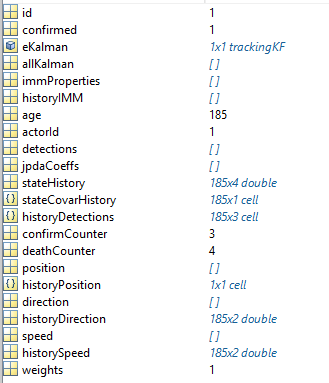

function track=getNewTrack()

Tracks have following properties:

- id:unique ID for every track

track.id=[];

confirmed: a flag that show if the track is confirmed

track.confirmed=0;

eKalman: contains the current state and state covariance of the track

track.eKalman=[];

allKalman: contains the three kalman filters used for IMM estimation

track.allKalman=[];

immProperties: contains the current mode probabilities $\mu_j$and the model transition probabilities $p_{ij}$ regarding IMM estimation

track.immProperties=[];

historyIMM: stores the IMM mode probabilities $\mu_j$

track.historyIMM=[];

age: number of time steps the track exists

track.age=0;

actorId: if a specific actor profile was detected

track.actorId=0;

detections: detections that are currently assigned to this track

track.detections=[];

jpdaCoeffs: current JPDA coefficients for all detections

track.jpdaCoeffs=[];

stateHistory: history of the tracks state

track.stateHistory=[];

stateCovarHistory: history of the tracks state covariance

track.stateCovarHistory=[];

historyDetections: history of detections that were assigned to this track

track.historyDetections={};

confirmCounter: counts how often a detection got assigned to this track

track.confirmCounter=0;

deathCounter: Counts down when no detection was assigned to a track. Track is deleted when it reaches zero.

track.deathCounter=2;

position: current position

track.position=[];

historyPosition: position history 

track.historyPosition={[]};

direction: current direction

track.direction=[];

historyDirection: direction history

track.historyDirection=[];

speed: current velocity of the track

track.speed=[];

historySpeed: history of velocities

track.historySpeed=[];
end

Back to top.

Back to usage.

----------------------------------------------------------------------------------------------------------------------------------------------------------------------------